**Exercise 3 ECE537 **

**Julie Jiang V00902597**

**Zixuan Deng V00971633**

## **Q1 Use Matlab’s neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.**

clear all;
% First we need to load data, A, B, C. 
muA=[0 4 7];
muB=[10 5 5];
muC = [-2 -5 -5];

covA = [6.5000, 2.1651, 1.2500;
    2.1651, 5.1250, 2.3816;
    1.2500, 2.3816, 2.3750];

covB = [3.0184, 0.4331, -1.4481;
    0.4331, 0.9436, -0.6456;
    -1.4481, -0.6456, 1.2880];

covC = [6.8928, -1.3750, 3.1945;
    -1.3750, 3.3572, 0.6945;
    3.1945, 0.6945, 3.7500];
% Get data A B C. 
A= trans(Gaussion_Data(1000,3,muA, covA), muA, covA);
B= trans(Gaussion_Data(1000,3,muB, covB), muB, covB);
C= trans(Gaussion_Data(1000,3,muC, covC), muC, covC);
Data = [A;B;C];
% Targets = [ repmat('A',1000,1); repmat('B',1000,1);repmat('C',1000,1)];
% Label = [ repmat(1,1000,1); repmat(2,1000,1);repmat(3,1000,1)]
% Data and Target must the same size....
label_A = [1, 0, 0];
label_B = [0, 1, 0];
label_C = [0, 0, 1];

Targets = [repmat(label_A, 1000, 1); repmat(label_B, 1000, 1); repmat(label_C, 1000, 1)]

Targets =      1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0


**The Simple Script Generated from nprtool.**

%nprtool

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 28-May-2021 13:27:45
%
% This script assumes these variables are defined:
%
%   Data - input data.
%   Targets - target data.

x = Data';
t = Targets';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x)

y =     0.9997    0.9995    0.9998    0.9997    0.9995    0.9998    0.9999    0.9970    0.9996    0.9987    0.9999    0.9875    0.9997    0.9995    0.9920    0.9996    0.9998    0.9999    0.9994    0.9998    0.9999    0.9998    0.9995    0.9994    0.9998    0.9992    0.9997    0.9581    0.9998    0.9999    0.9999    0.9984    0.9997    0.9996    0.9611    0.9929    0.9996    0.9998    0.9985    0.9994    0.9999    0.9997    0.9998    0.9998    0.9988    0.9998    0.9992    0.9998    0.9999    0.9998
    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0002    0.0008    0.0000    0.0120    0.0000    0.0003    0.0069    0.0001    0.0000    0.0000    0.0003    0.0001    0.0000    0.0000    0.0001    0.0004    0.0000    0.0004    0.0001    0.0407    0.0001    0.0000    0.0001    0.0013    0.0001    0.0002    0.0381    0.0019    0.0000    0.0001    0.0012    0.0000    0.0000    0.0001    0.0000    0.0001    0.0009    0.0001    0.0000    0.0001    0.0000    0

e = gsubtract(t,y)

e =     0.0003    0.0005    0.0002    0.0003    0.0005    0.0002    0.0001    0.0030    0.0004    0.0013    0.0001    0.0125    0.0003    0.0005    0.0080    0.0004    0.0002    0.0001    0.0006    0.0002    0.0001    0.0002    0.0005    0.0006    0.0002    0.0008    0.0003    0.0419    0.0002    0.0001    0.0001    0.0016    0.0003    0.0004    0.0389    0.0071    0.0004    0.0002    0.0015    0.0006    0.0001    0.0003    0.0002    0.0002    0.0012    0.0002    0.0008    0.0002    0.0001    0.0002
   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0002   -0.0008   -0.0000   -0.0120   -0.0000   -0.0003   -0.0069   -0.0001   -0.0000   -0.0000   -0.0003   -0.0001   -0.0000   -0.0000   -0.0001   -0.0004   -0.0000   -0.0004   -0.0001   -0.0407   -0.0001   -0.0000   -0.0001   -0.0013   -0.0001   -0.0002   -0.0381   -0.0019   -0.0000   -0.0001   -0.0012   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0009   -0.0001   -0.0000   -0.0001   -0.0000   -0

performance = perform(net,t,y)

performance = 0.0051

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

## **Q2 Plot the decision boundaries created by this trained neural network classifier and discuss the ”correctness” of these boundaries versus the Bayesian class boundaries that were generated in Exercise 1.**

box = vol3D([-15 20 -15 20 -15 20],150)

box =   -15.0000  -15.0000  -15.0000
  -15.0000  -15.0000  -14.7651
  -15.0000  -15.0000  -14.5302
  -15.0000  -15.0000  -14.2953
  -15.0000  -15.0000  -14.0604
  -15.0000  -15.0000  -13.8255
  -15.0000  -15.0000  -13.5906
  -15.0000  -15.0000  -13.3557
  -15.0000  -15.0000  -13.1208
  -15.0000  -15.0000  -12.8859


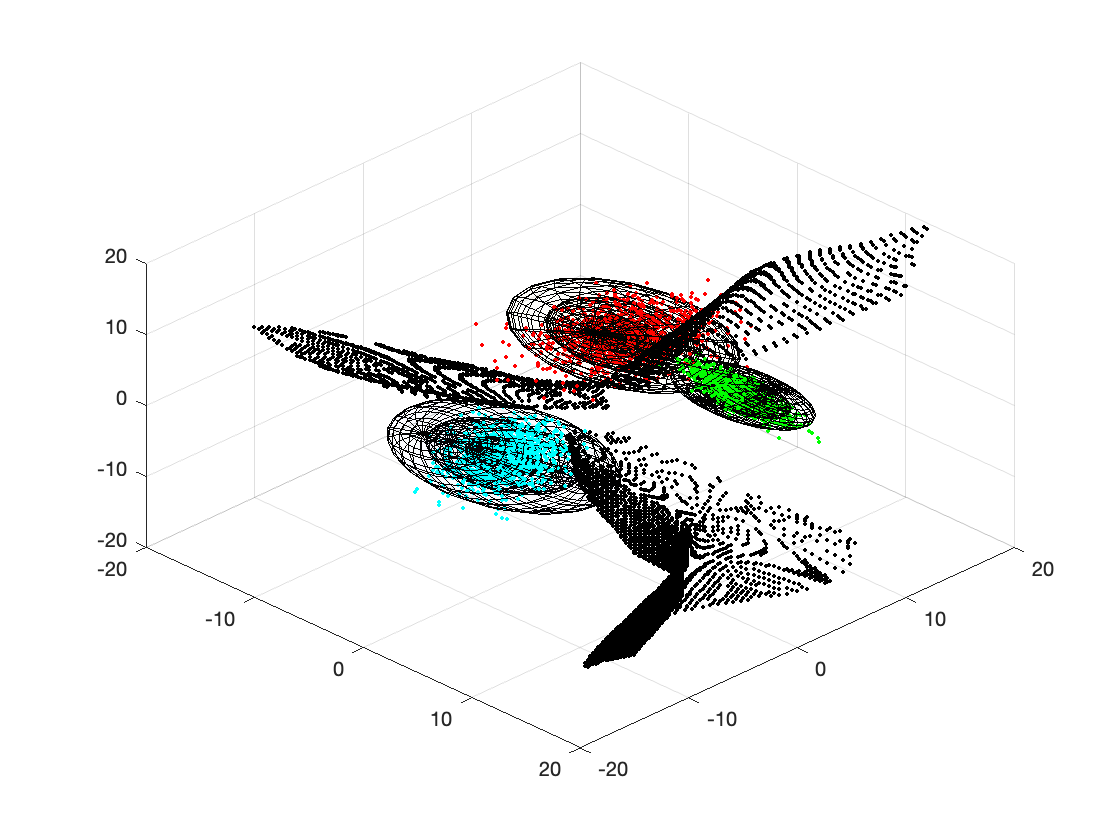

data_nn = net(box');
[boundary_AB, boundary_BC, boundary_AC] = nn_bound(data_nn', 0.01);

plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB,boundary_BC,boundary_AC,box)

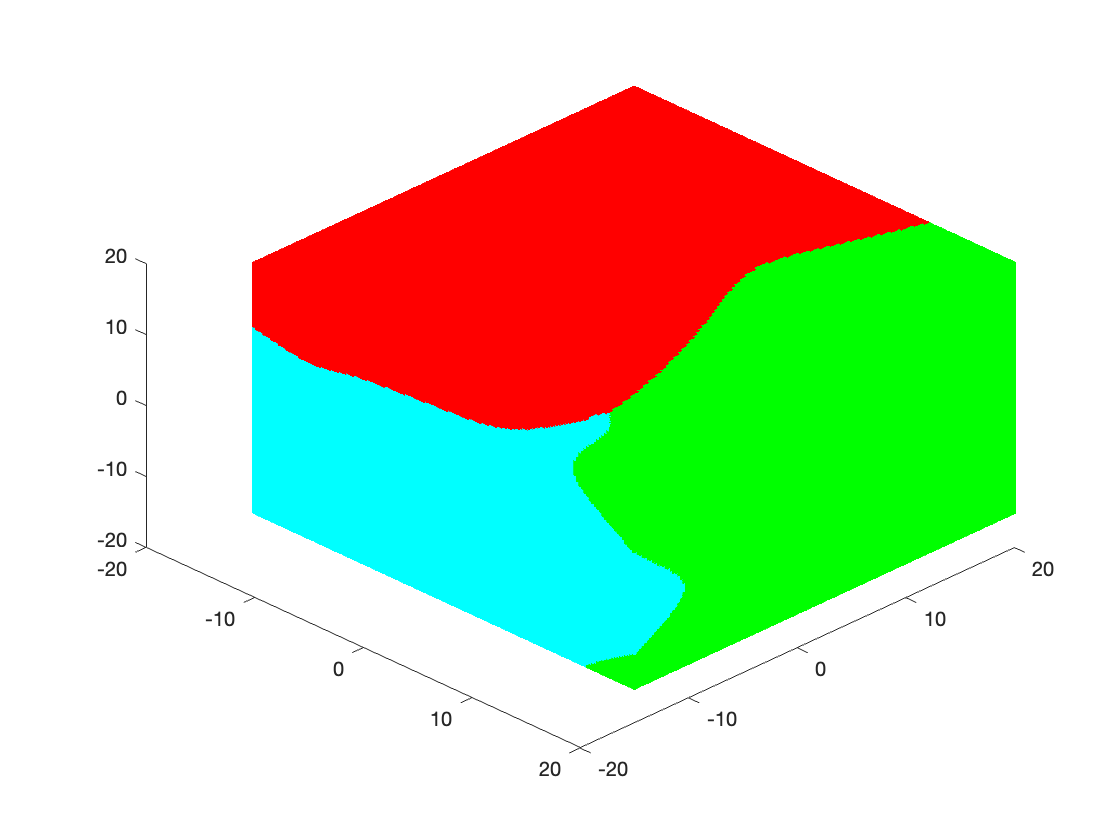


[class_a, class_b, class_c]=classifier_nn(data_nn');
plot_box(class_a,class_b,class_c,box)

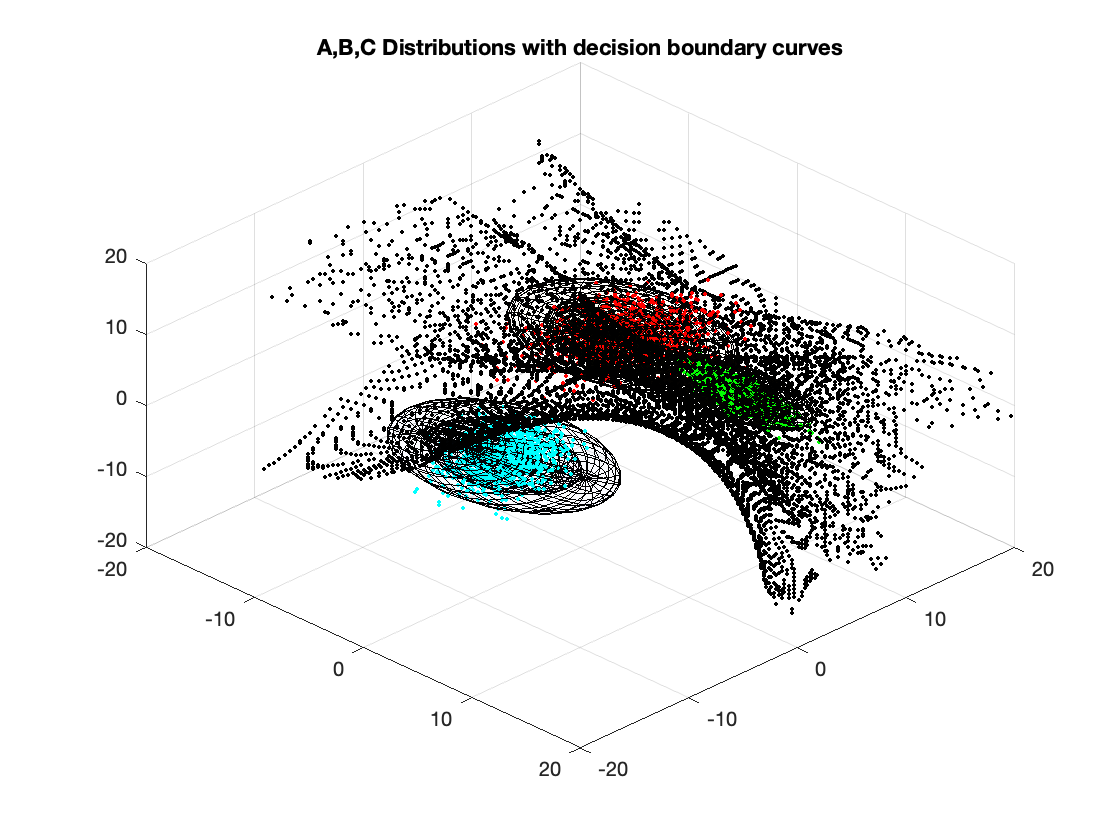

prior_a = 1/3;
prior_b = 1/3;
prior_c = 1/3;

% Get boundaries and plot the boundaries. 
[boundary_AB, boundary_BC, boundary_AC] = bayes_bound(muA,covA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB,boundary_BC,boundary_AC,box)
title('A,B,C Distributions with decision boundary curves')

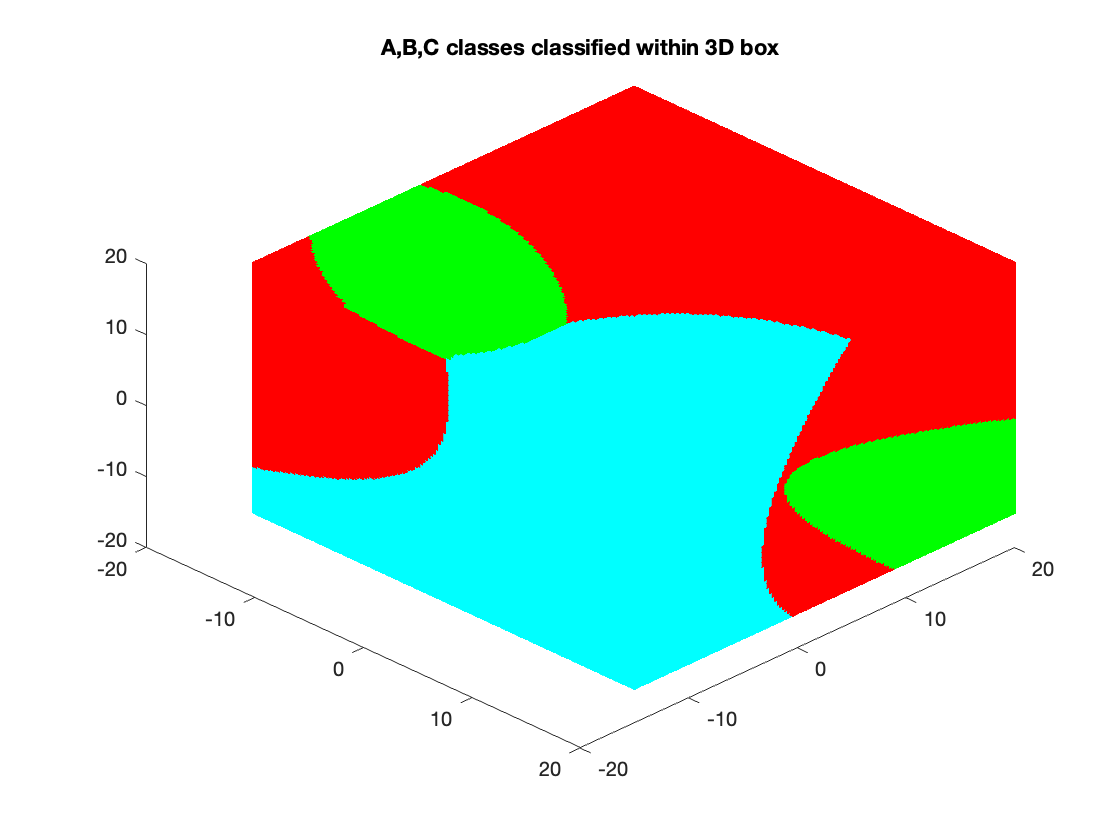


[class_a, class_b, class_c]=classifier(muA,covA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a,class_b,class_c,box)
title('A,B,C classes classified within 3D box')
hold off;
hold off

### Q2 Discussion

The neural network is learning the minimum empirical error, the bayes boundaries has minimum risk. According to the decision boundaries shows in the neural network, we could see the decision boundaries shows in the bayes is more complex and precise. The neural network is not support for the probability for each class, and bayes can depend on probability of the class given the suitable boundaries. However, we cannot say whoes boundaries is wrong or correct.

## **Q3 Discuss whether or not (and why) Matlab’s computation of the trained neural network’s error, as implemented within its neural net toolbox, is correct.**

%Error from toolbox is performance(means mse)
performance

performance = 0.0051

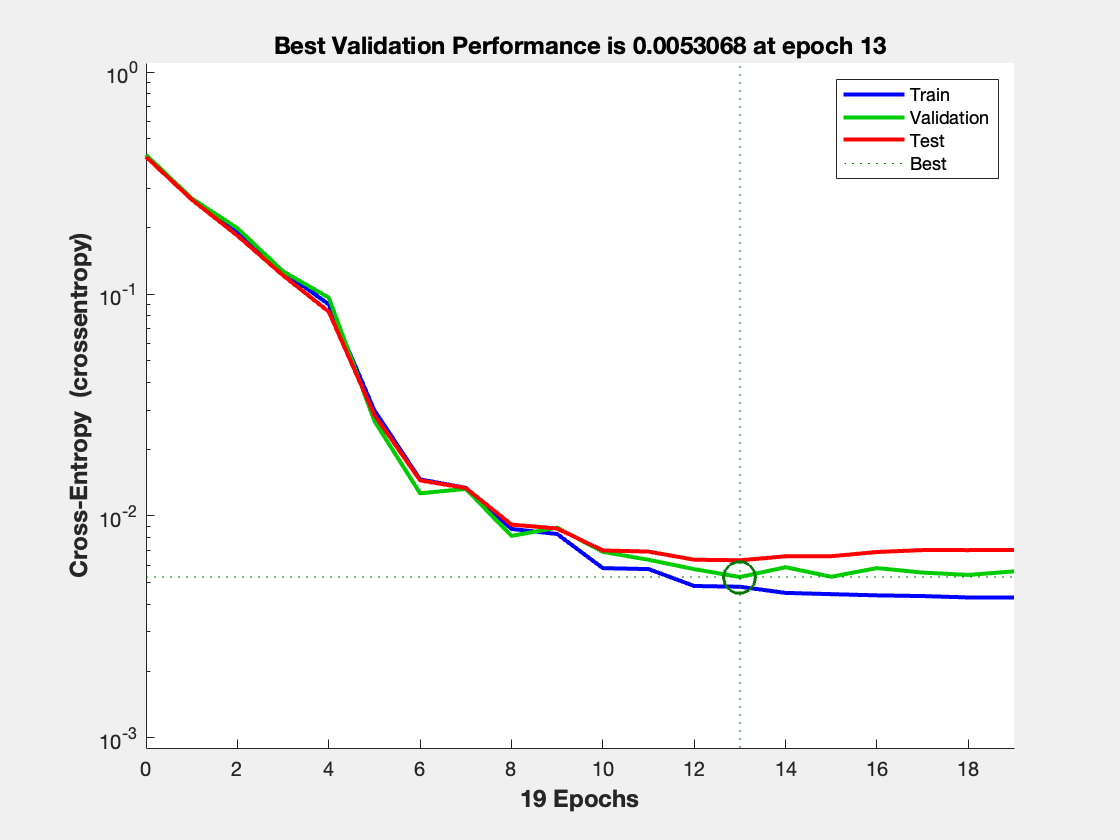



% %Calculate MSE
% D = abs(Targets'-y).^2;
% MSE = sum(D(:))/numel(Targets')
% 
% 
% errors = gsubtract(Targets, y');
% [max_errors, ~] = max(abs(errors), [], 2);
% MSE = sum((max_errors .* max_errors), 1) / length(max_errors);
% MSE
% 
% outref = mean(Targets')'
% MSEref = mse( Targets- outref )
%   %= mean( var(Targets',1) )
% 
% NMSE = mse(Targets-y')/ MSEref
%     %= 1 - Rsquare 

figure, plotperform(tr)

% figure, plottrainstate(tr)
% figure, ploterrhist(e)
% figure, plotconfusion(t,y)
% figure, plotroc(t,y)


The error should be correct, beacuse the neural network is trained on this data set to achieve the best effect. Even the start point is different each time, but this is the best result it can be achieve in this dataset. 

From those graphs, we could see that the performance of training, validation, test dataset follows similiar trend. The Neural Network we built do not have overfitting problem.  

## **Q4 Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries. **

hold off

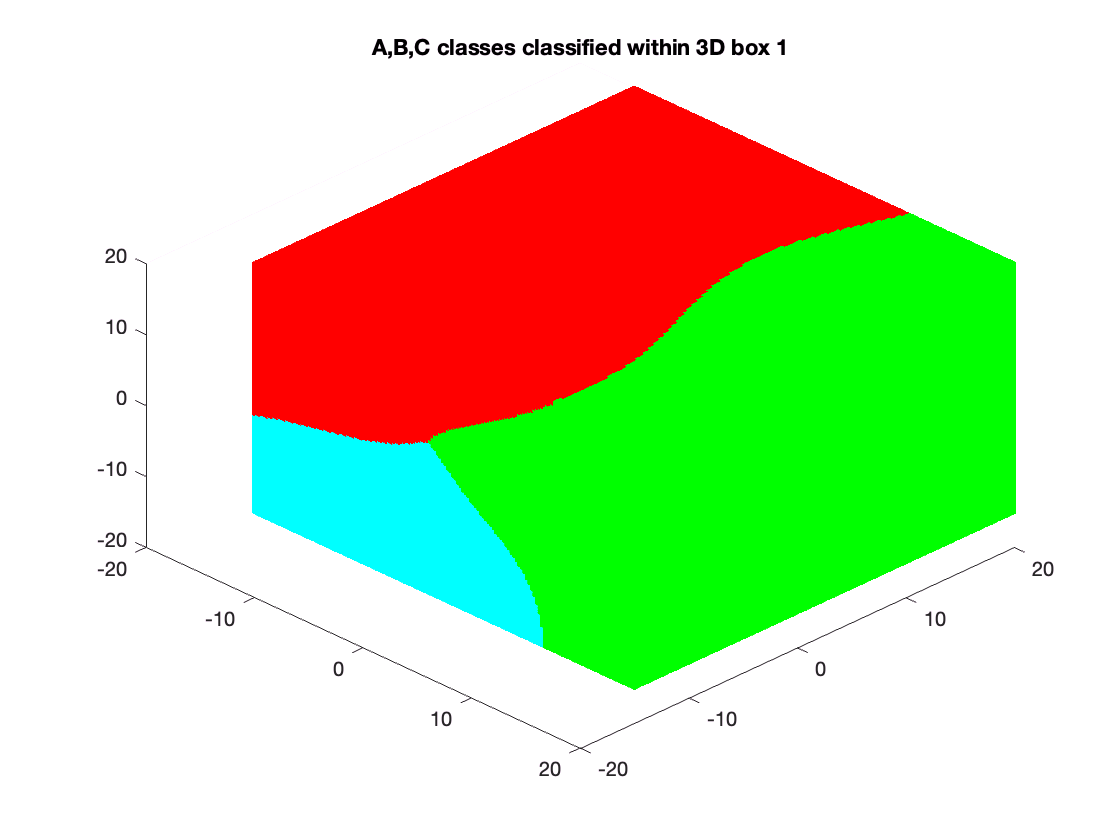

% clear cfg
%1
net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 1')

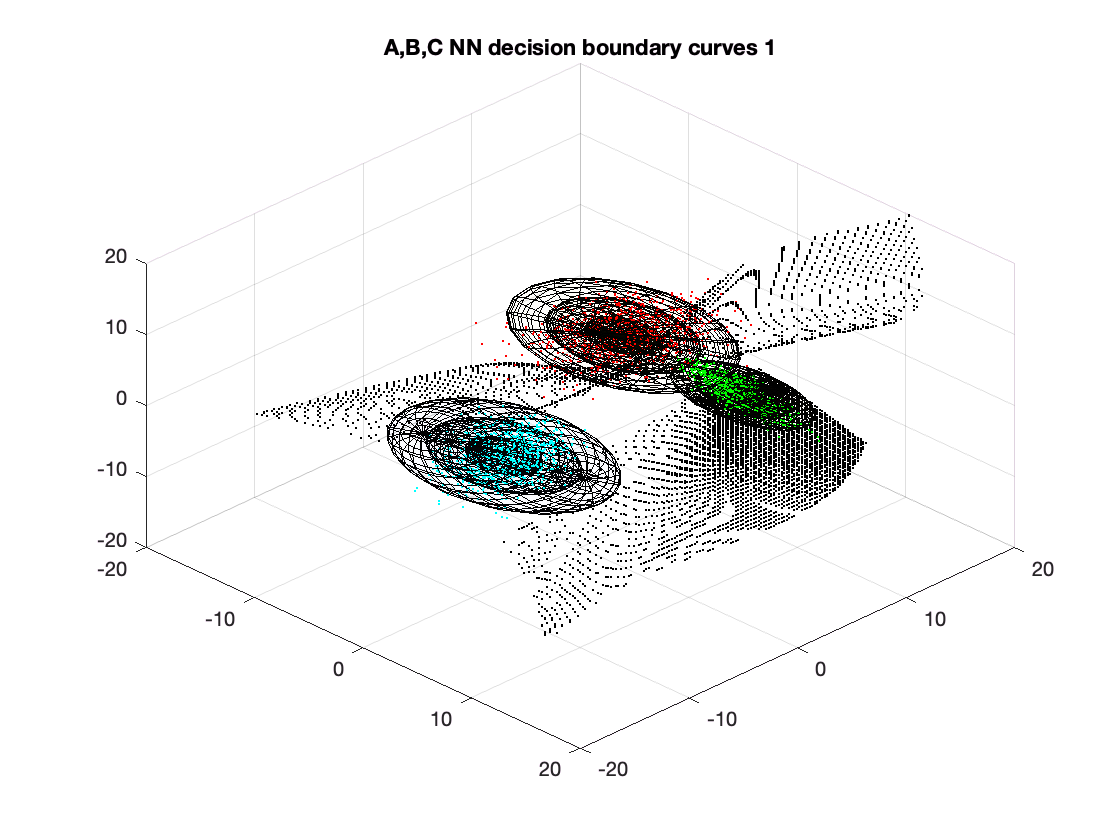


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 1')
hold off;

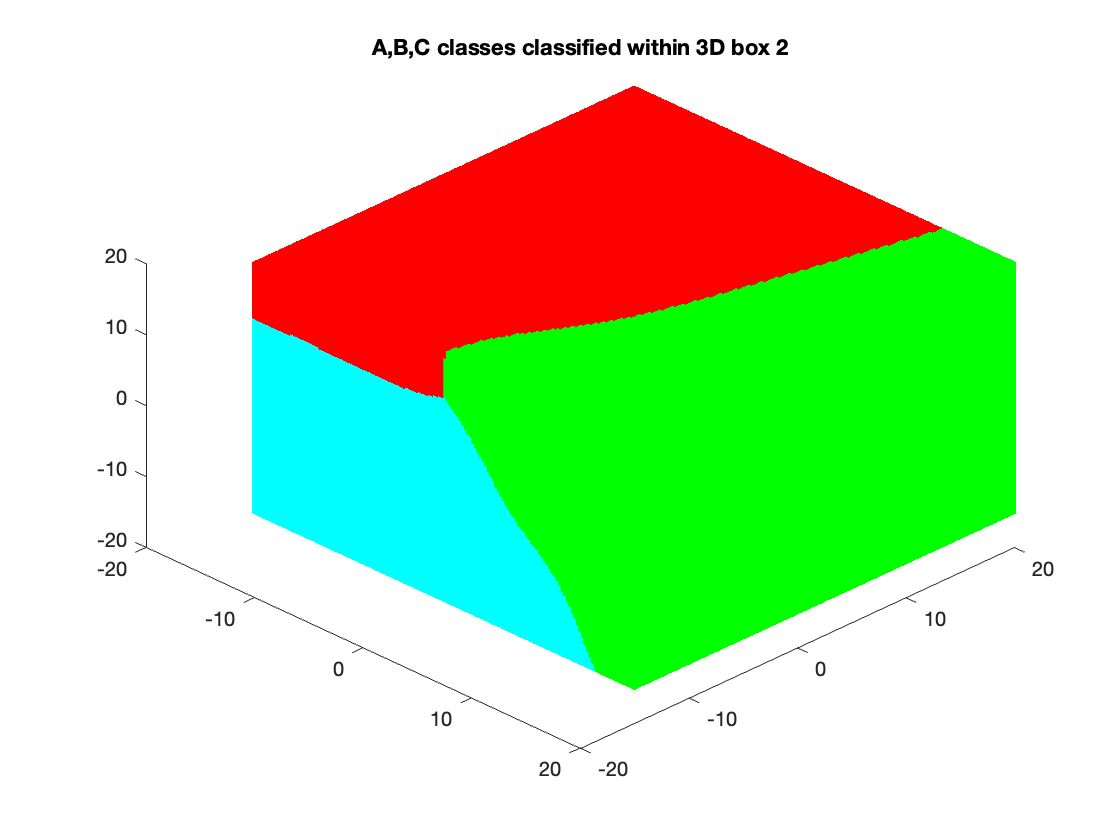

%2
net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 2')

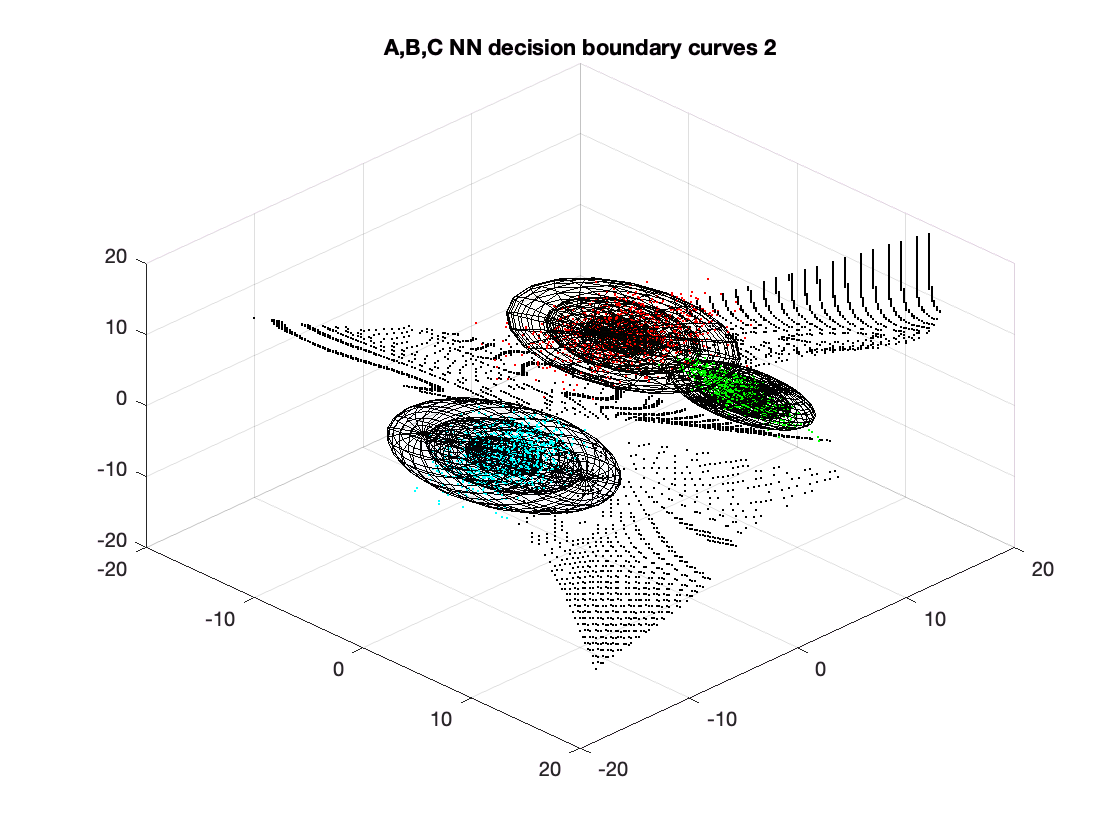


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 2')
hold off;

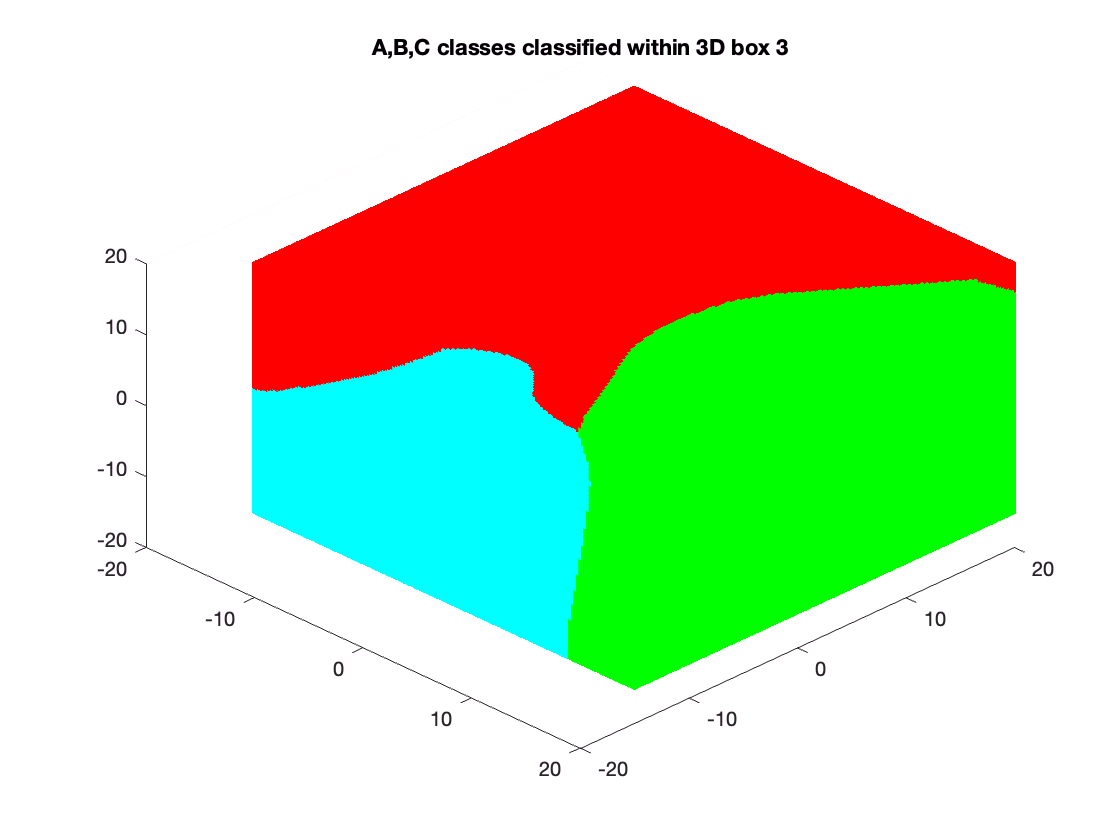


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 3')

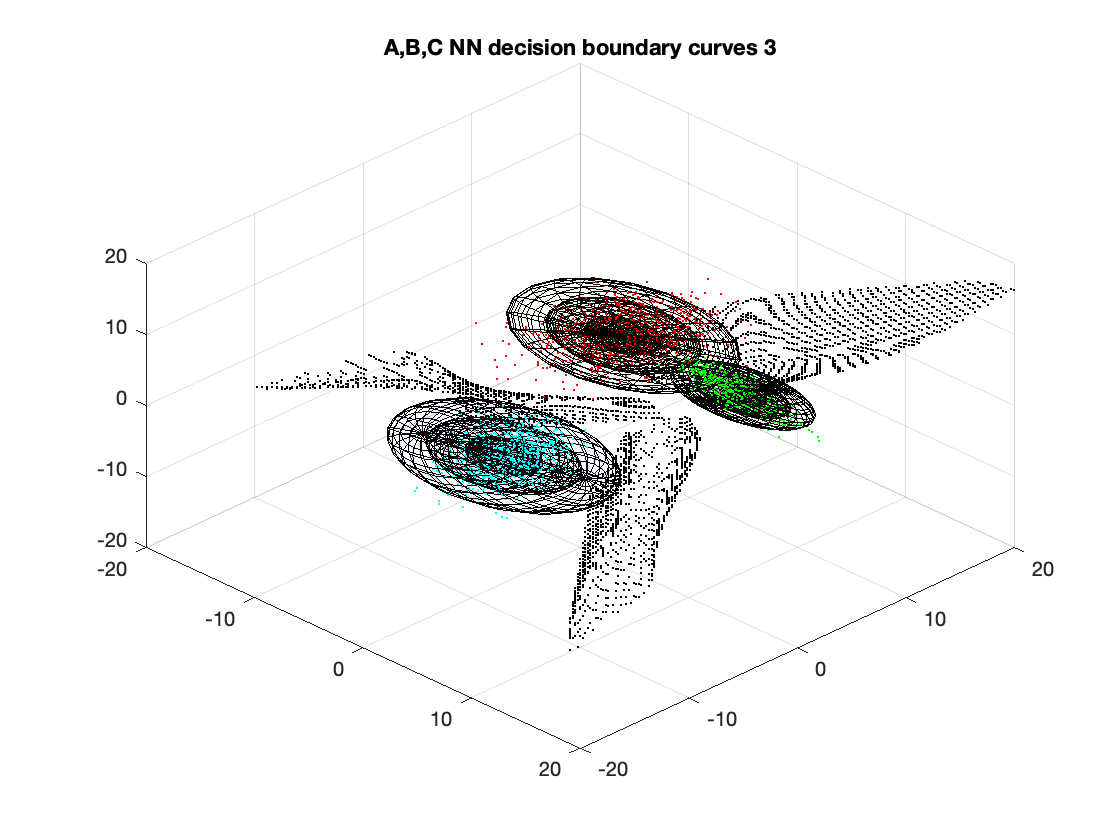


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 3')
hold off;

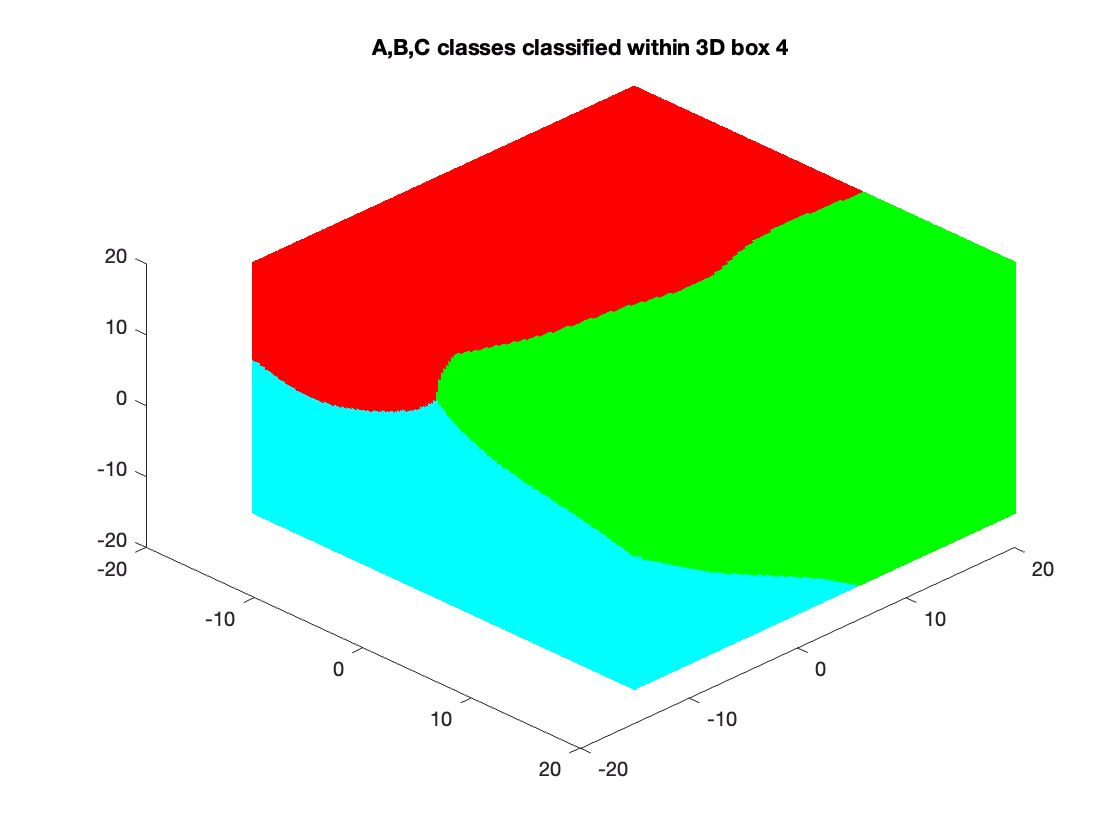


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 4')

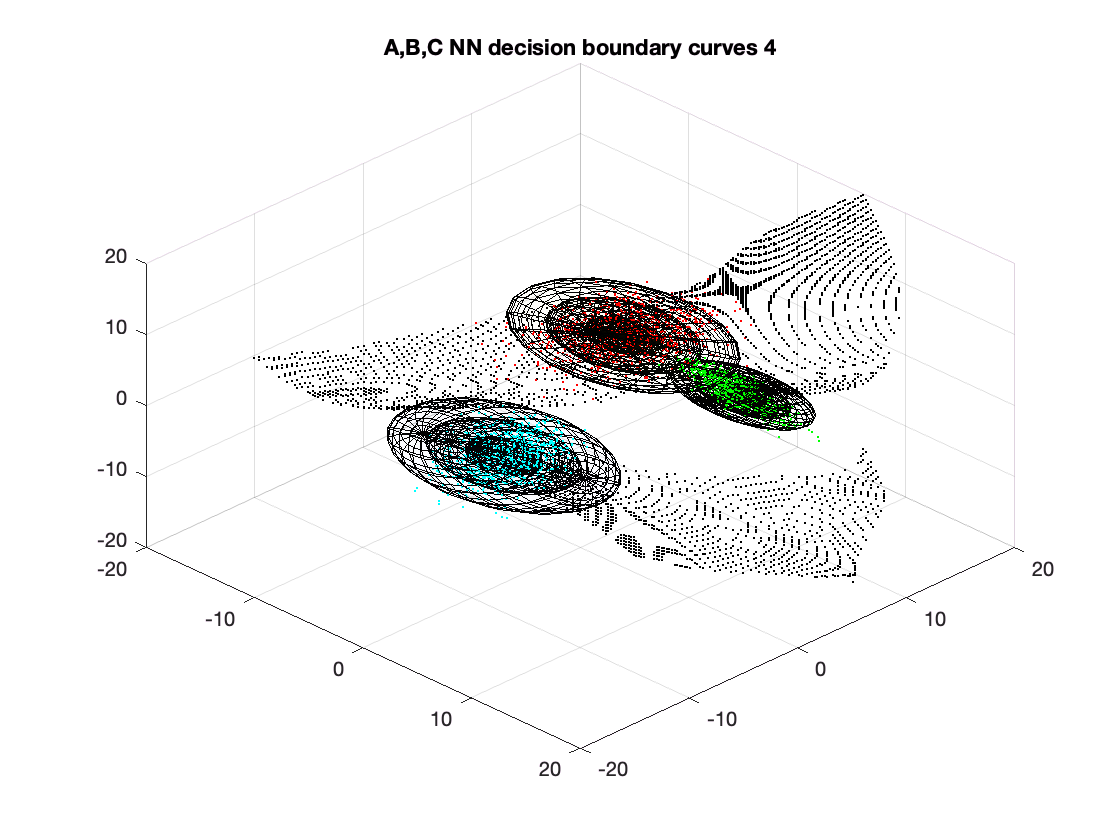


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 4')
hold off;

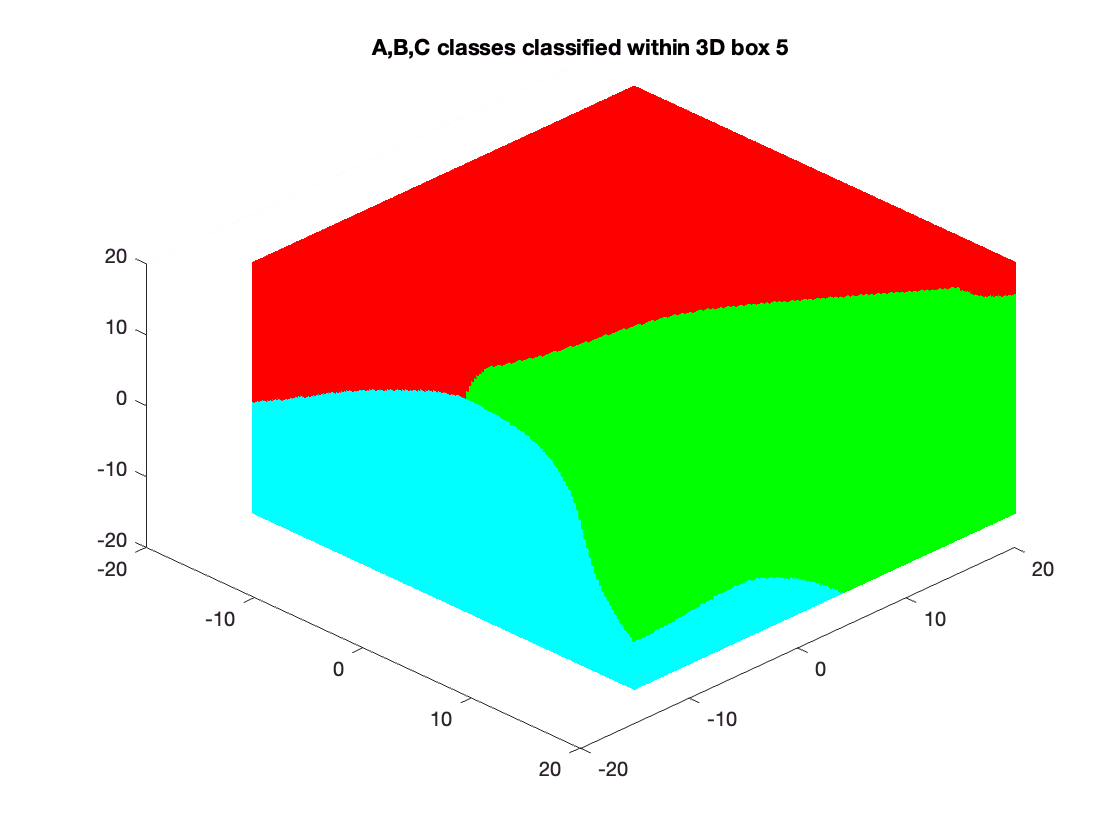


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 5')

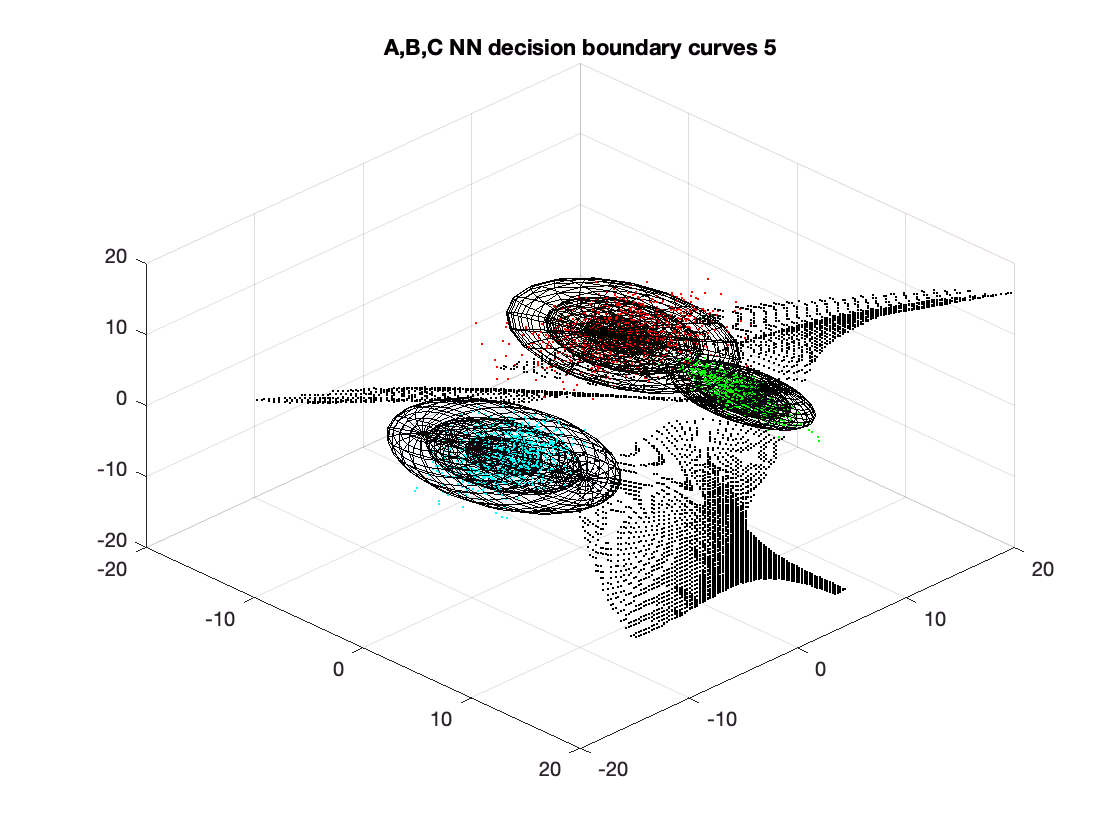


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 5')
hold off;

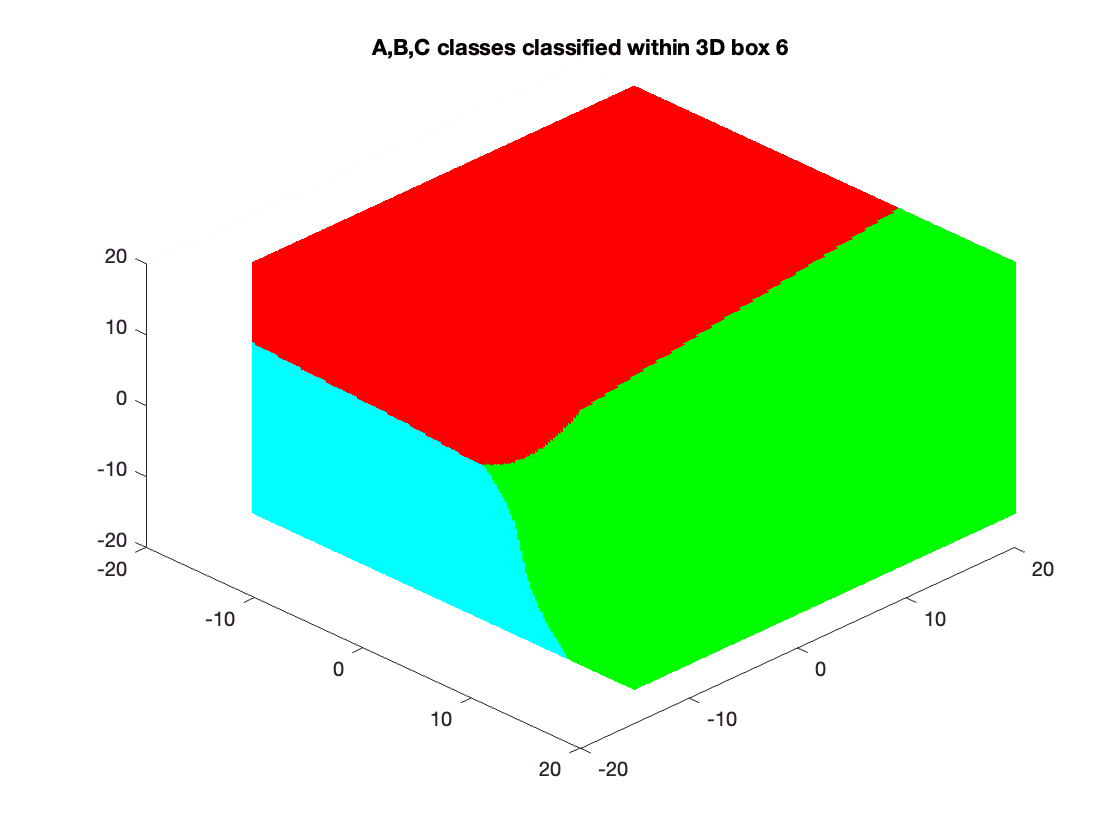


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 6')

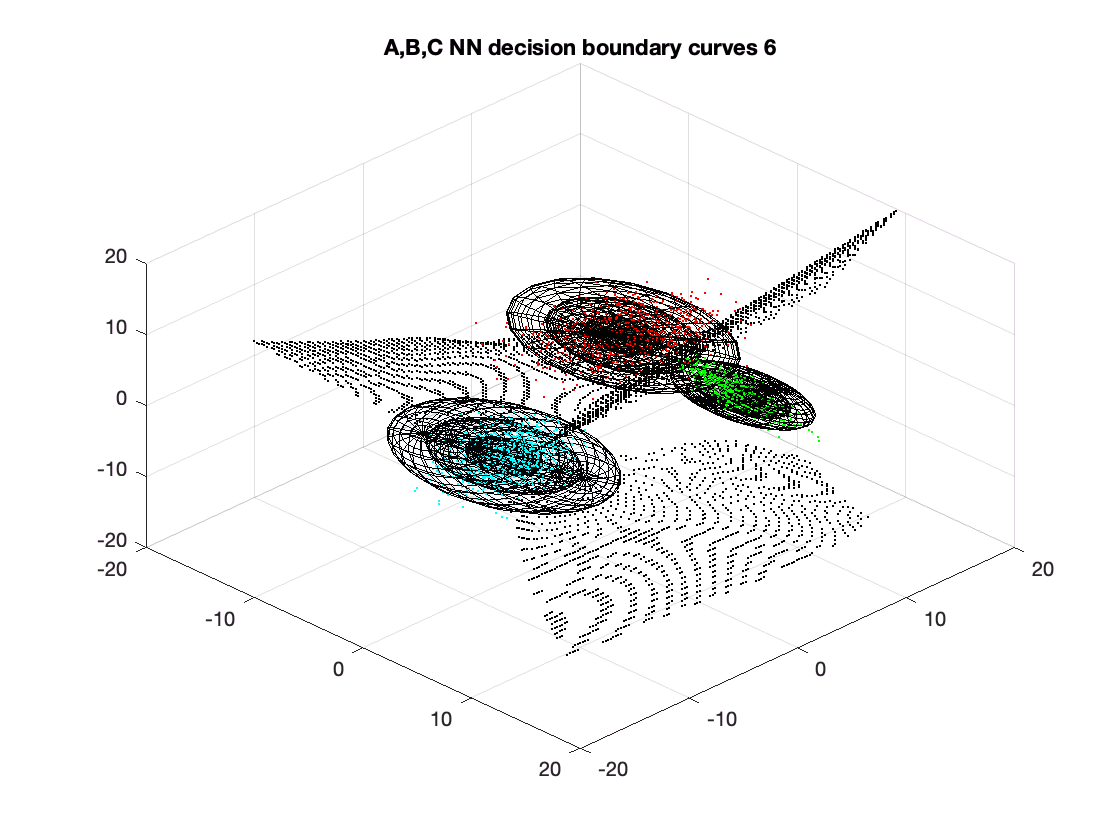


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 6')
hold off;

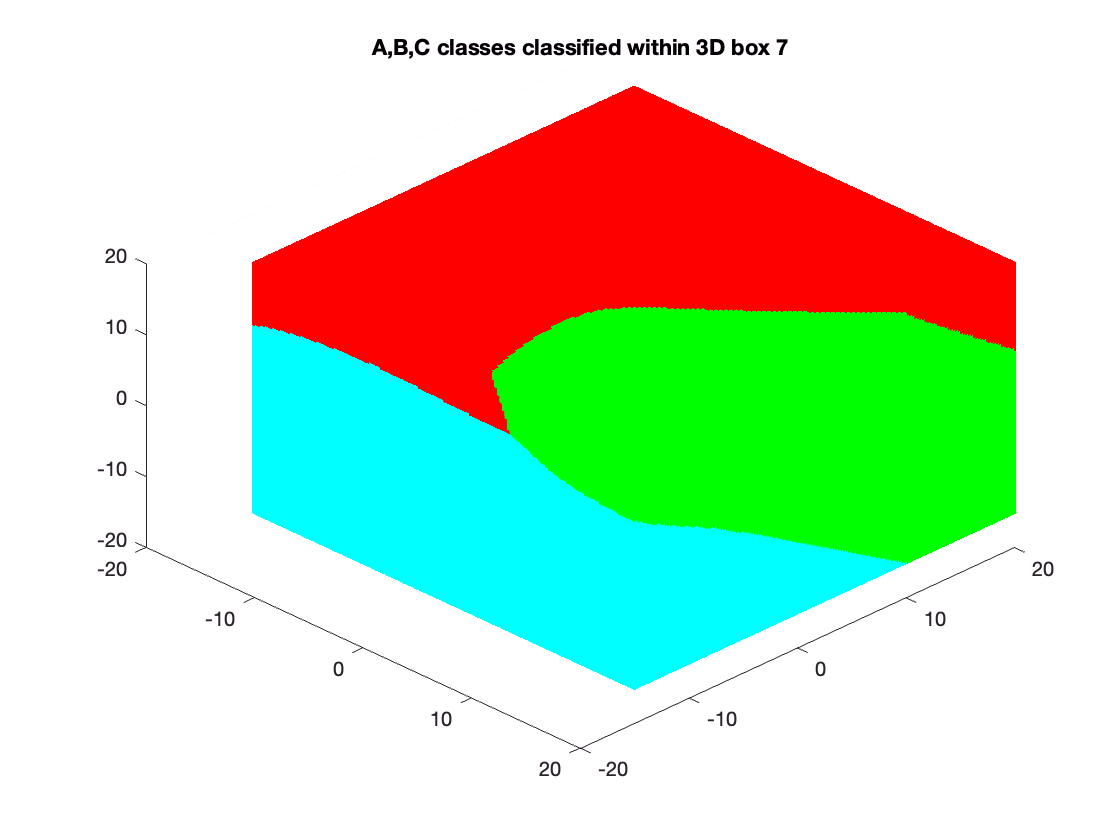


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 7')

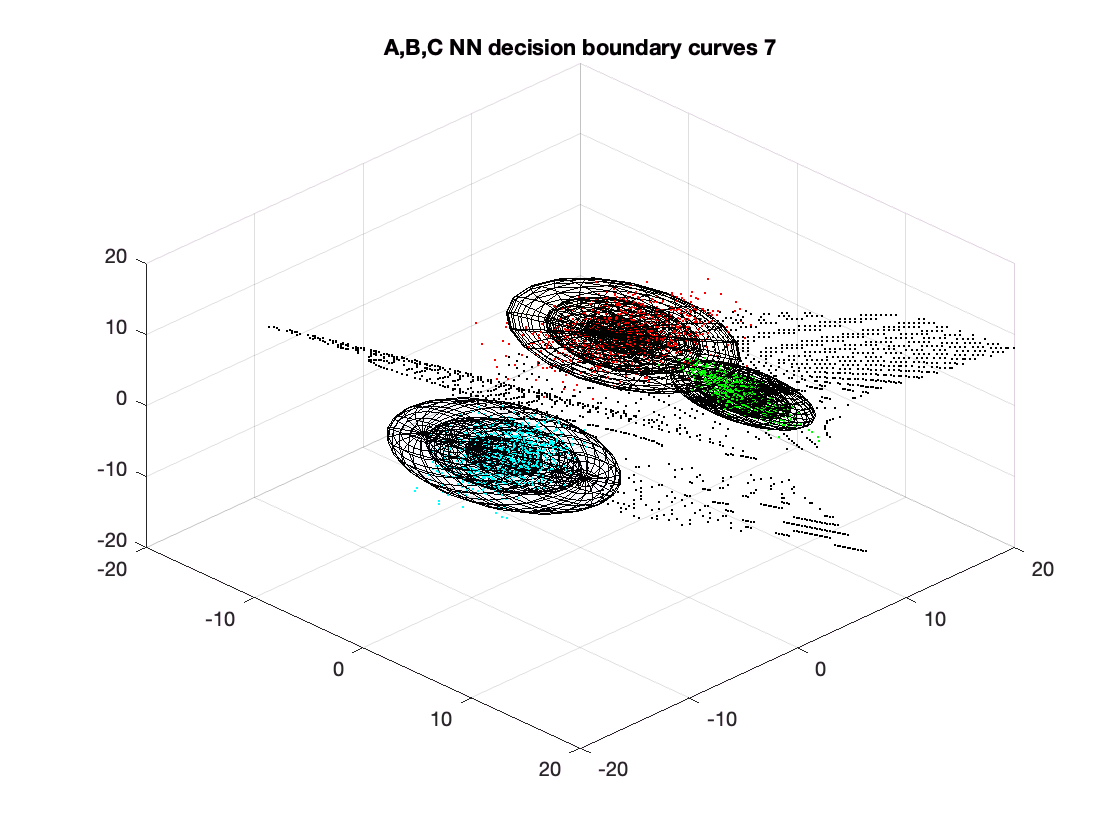


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 7')
hold off;

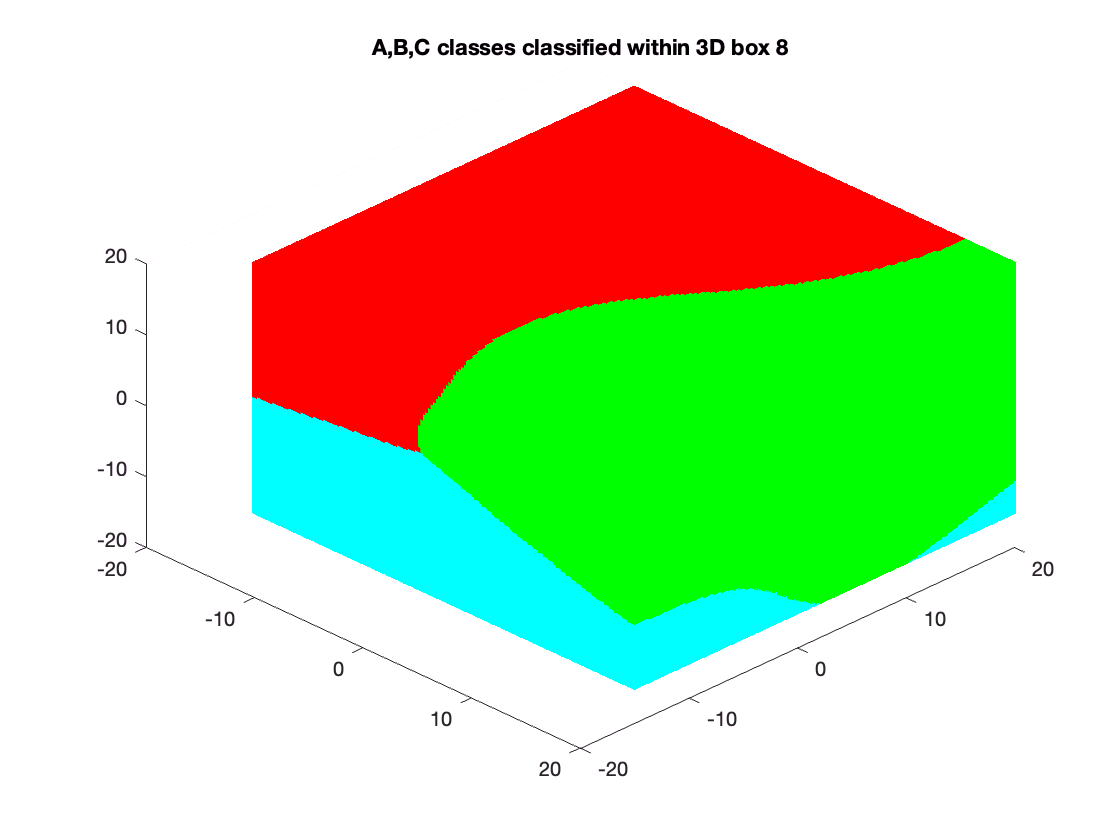


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 8')

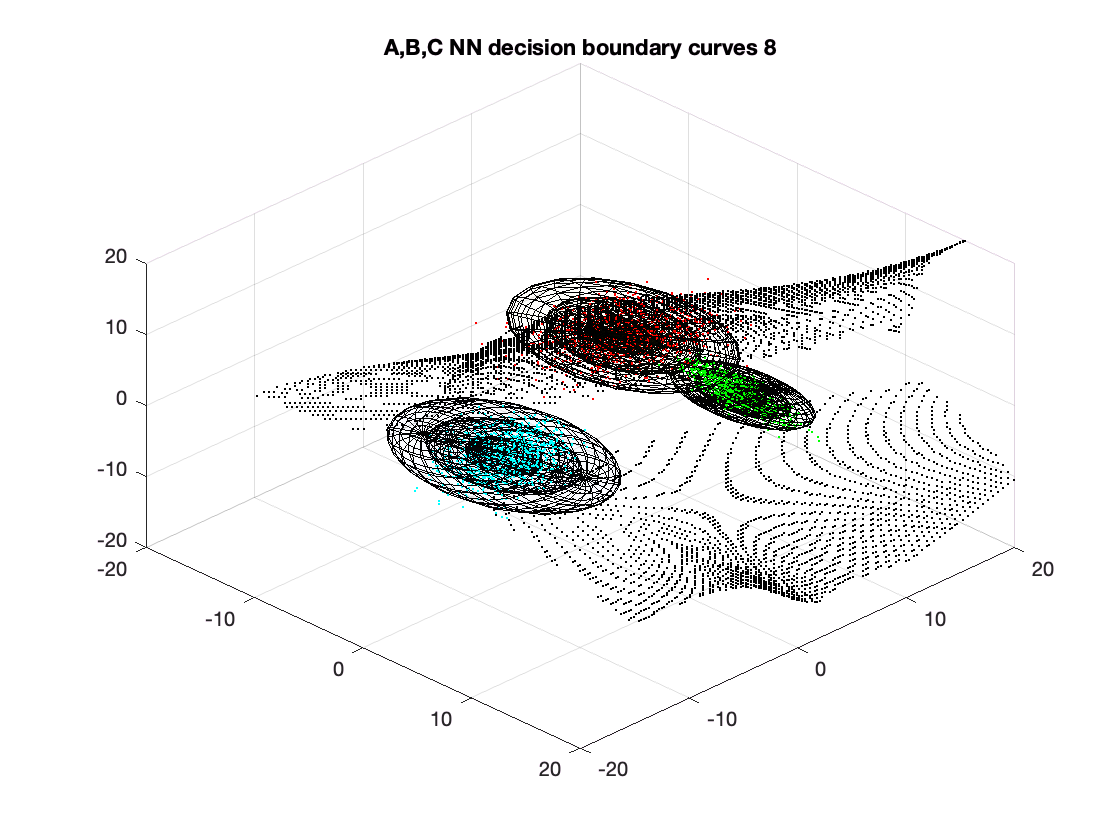


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 8')
hold off;

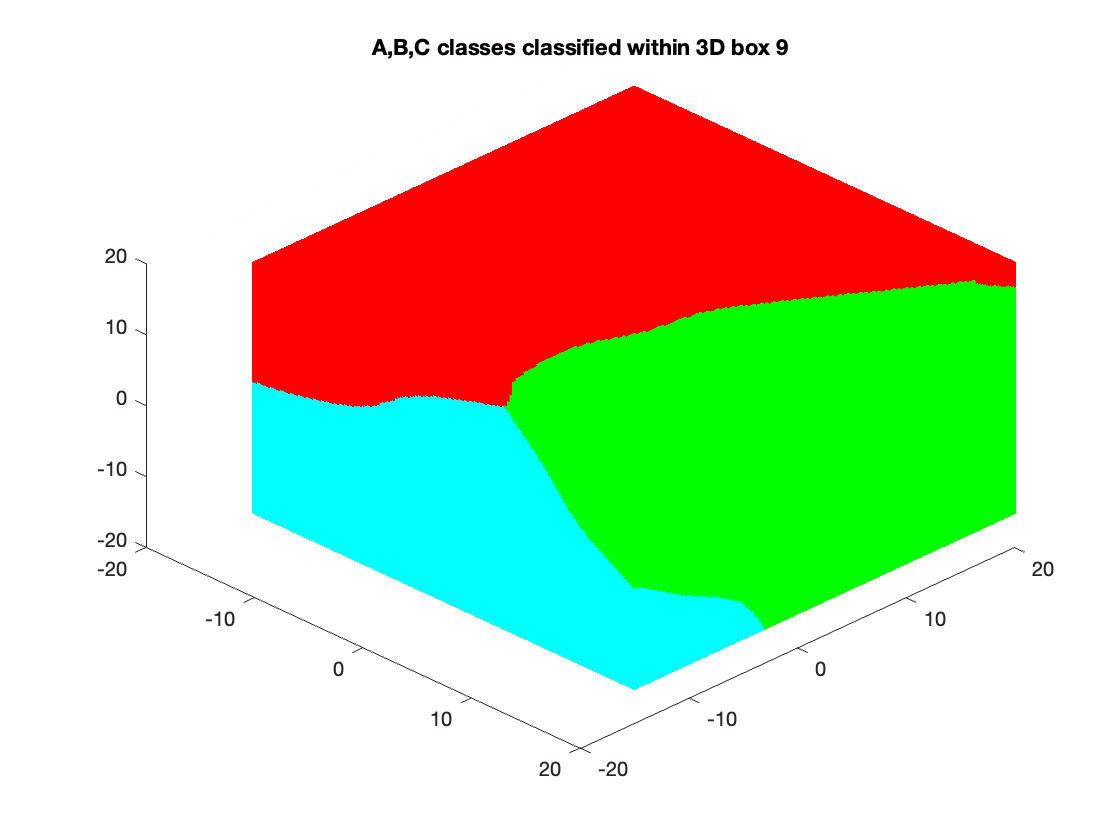


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 9')

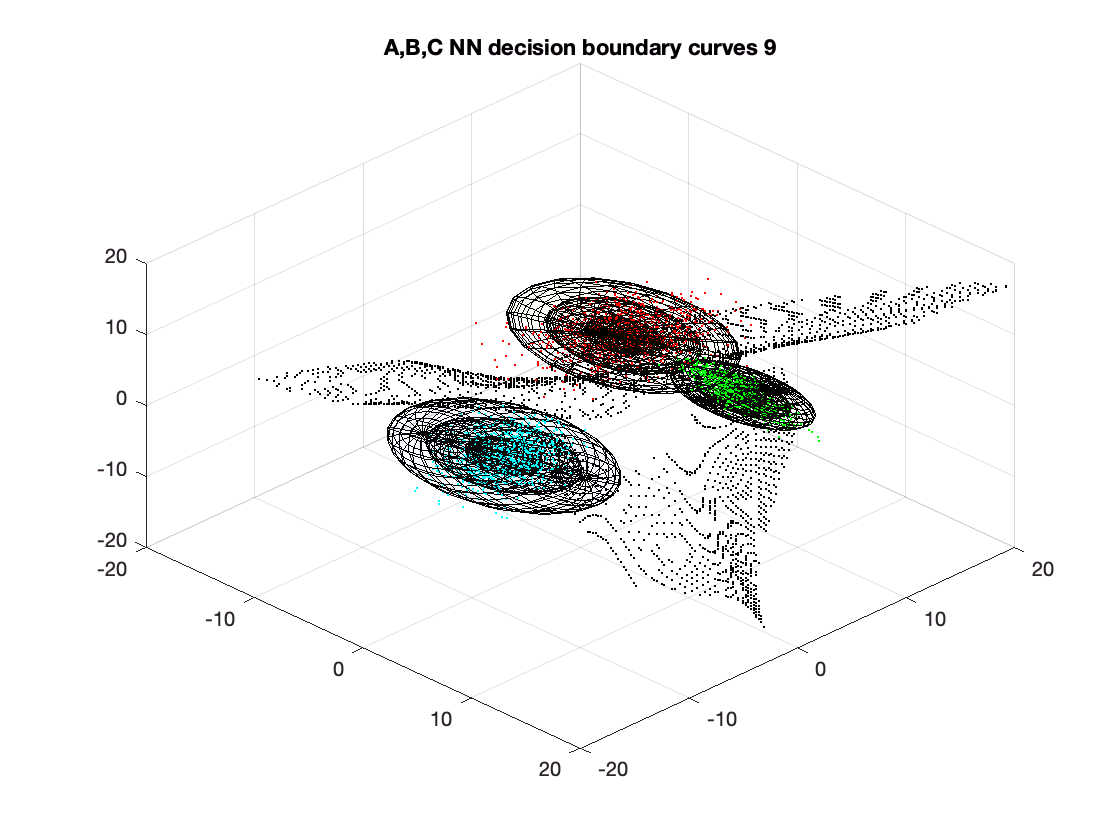


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 9')
hold off;

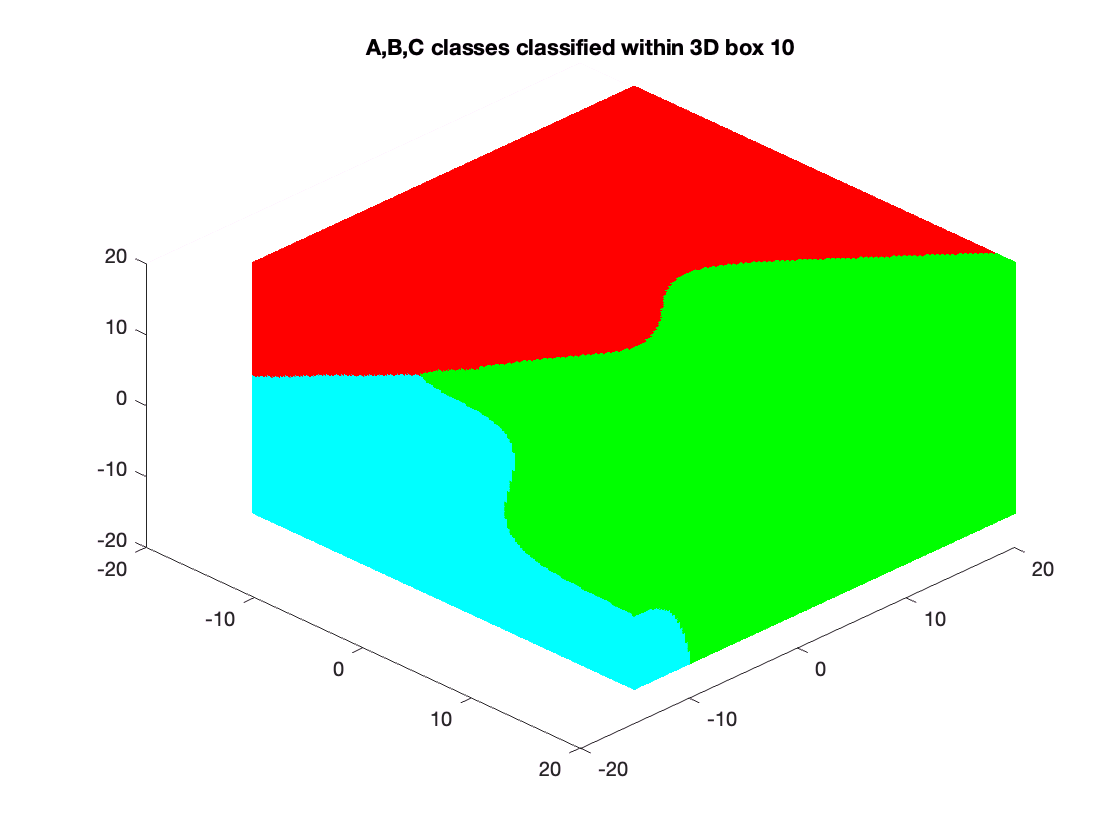


net_2=create_nn(Data', Targets', 10);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 10')

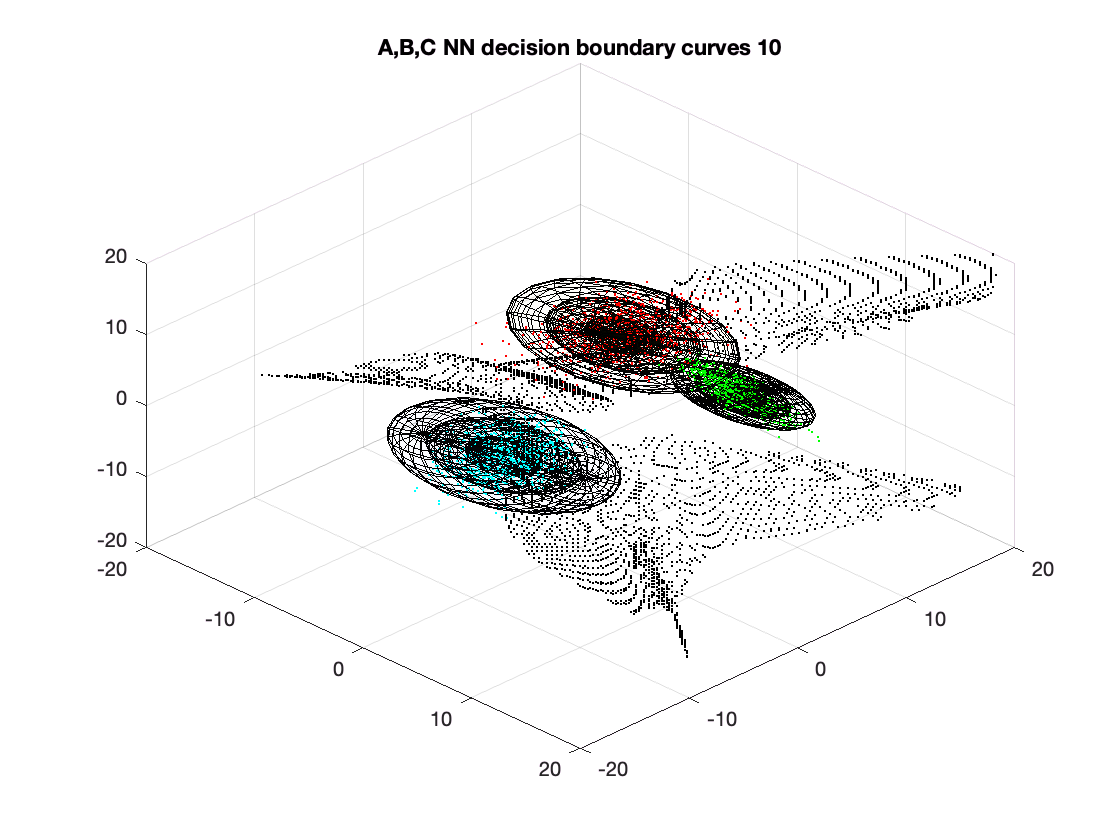


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 10')
hold off;

### **4a) Discuss what would occur relative to the produced decision boundaries if 100 different neural network training were conducted.**

As the experiment above, we can see 10 times network training has 10 different decision boundaries. The neural network generator by random seeds. Therefore, we training the 100 different neural network we may get 100 different decision boundaries.

### **4b) Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary. **

None of resulting neural network decision boundaries are worng or correct, Since the starting point is different, the plot of the decision boundary is different every time, and the neural network is depend on the number of hidden layer, so we can't say which plot is right and which is wrong.

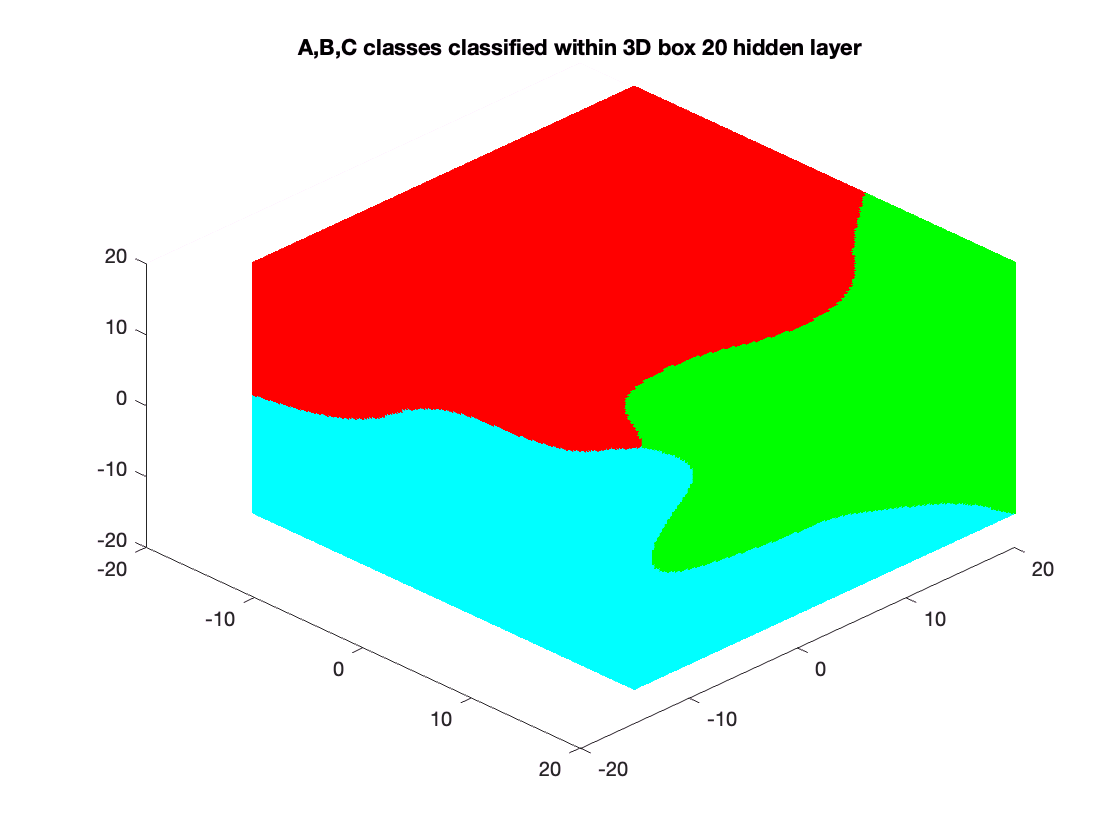

net_2=create_nn(Data', Targets', 20);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 20 hidden layer')

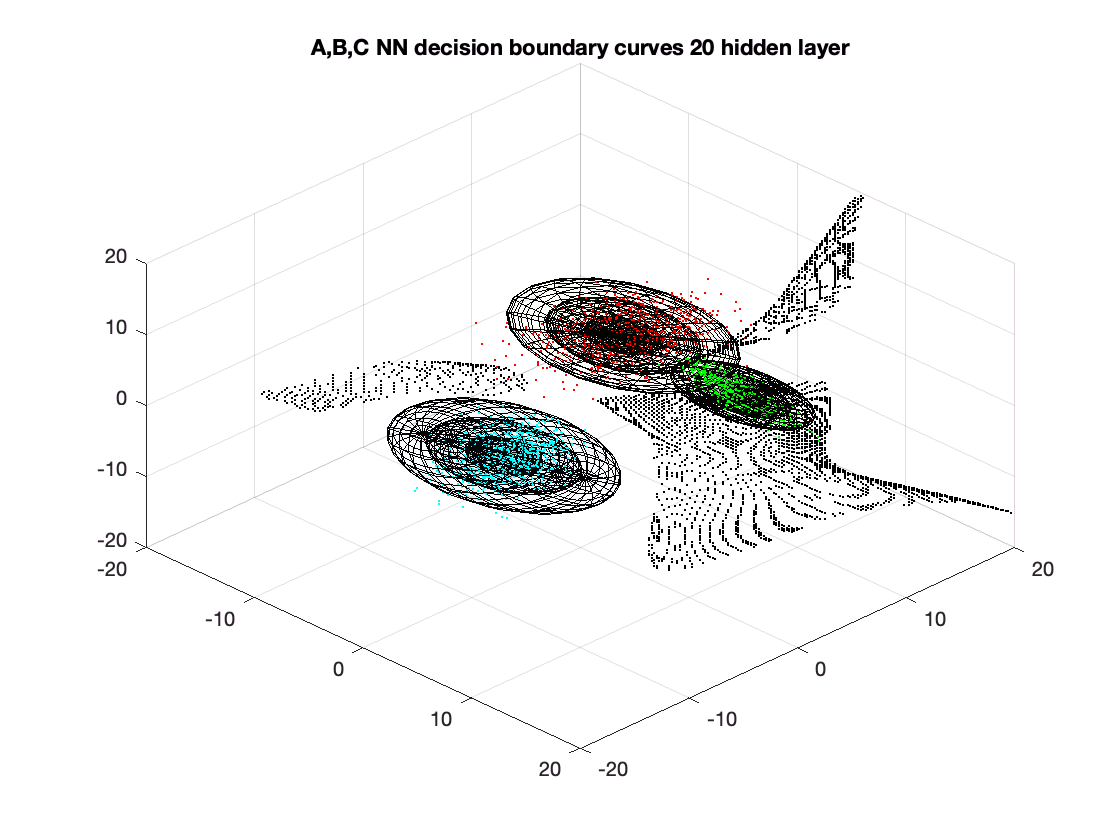


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 20 hidden layer')
hold off;

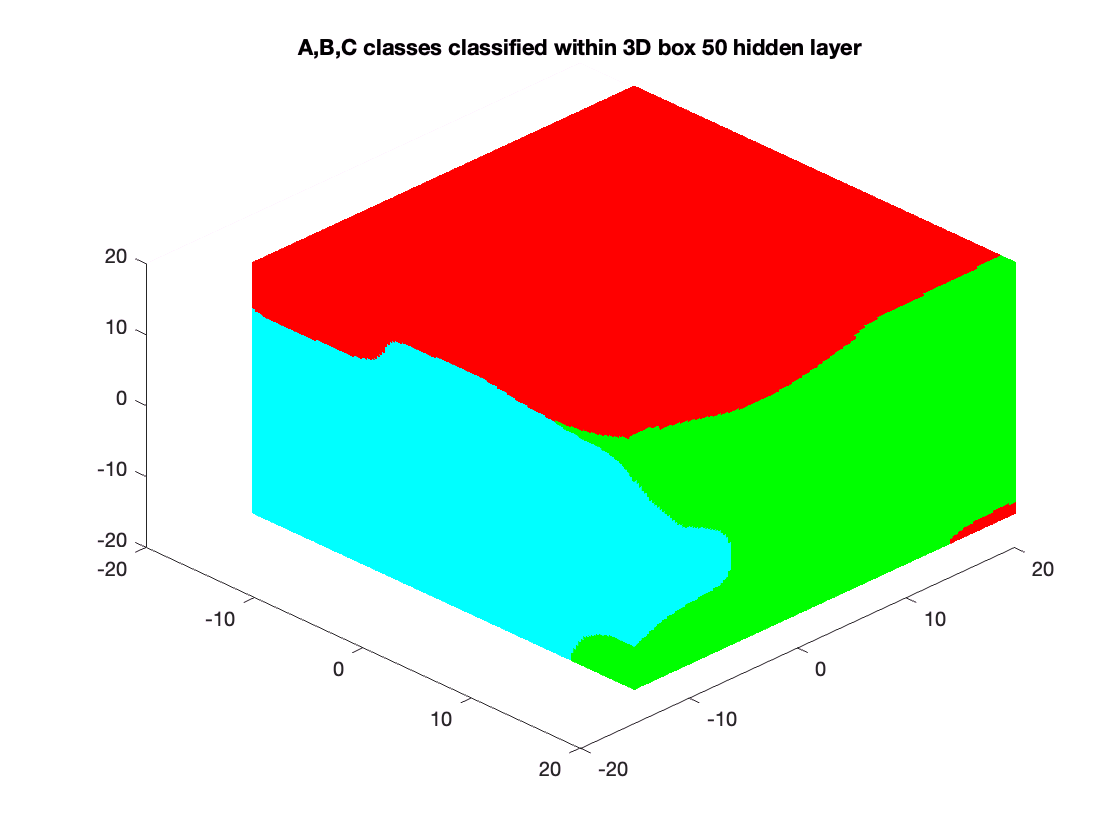


net_2=create_nn(Data', Targets', 50);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 50 hidden layer')

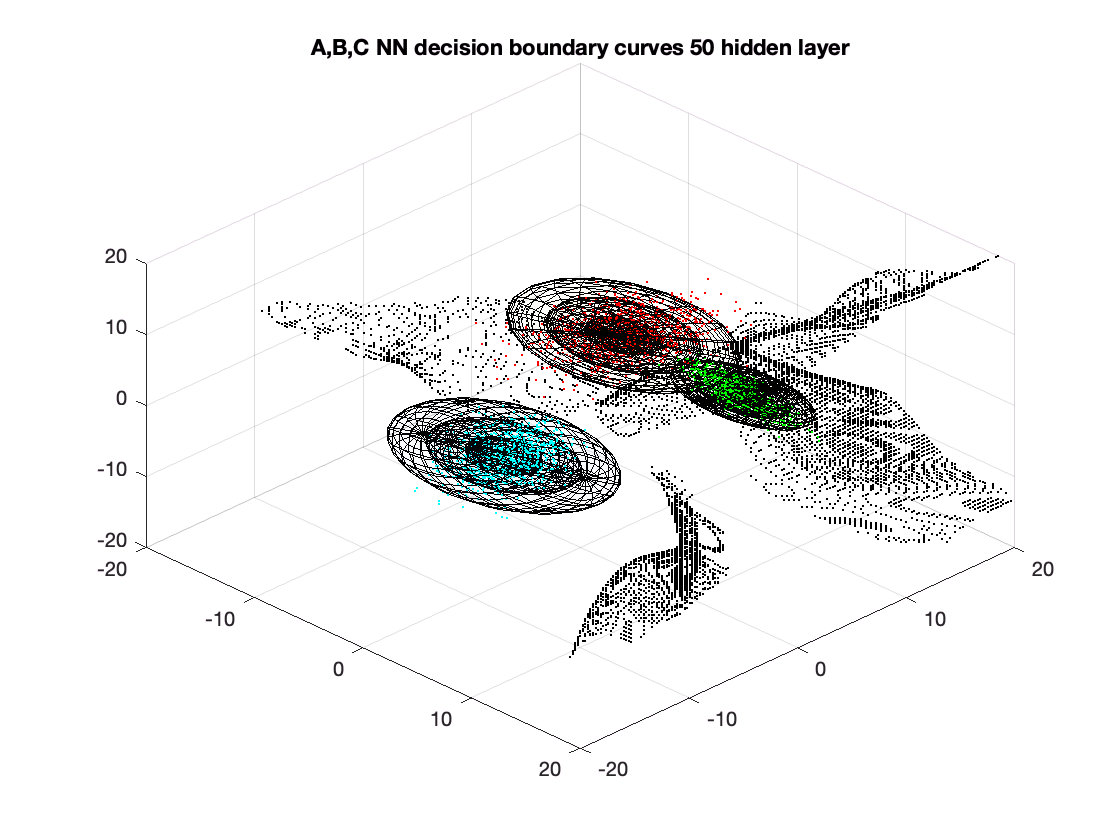


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 50 hidden layer')
hold off;

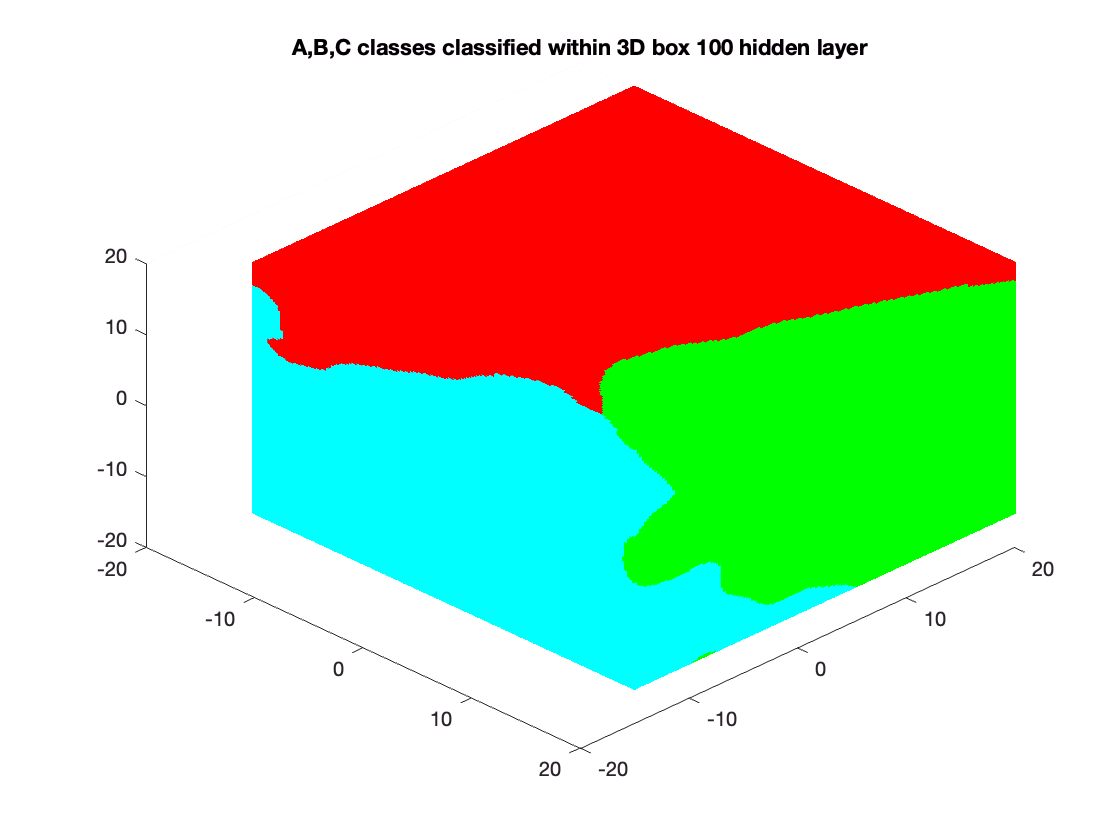


net_2=create_nn(Data', Targets', 100);
data_layer = net_2(box');
[boundary_AB_4, boundary_BC_4, boundary_AC_4] = nn_bound(data_layer', 0.01);

[class_a4, class_b4, class_c4]=classifier_nn(data_layer');
plot_box(class_a4,class_b4,class_c4,box)
title('A,B,C classes classified within 3D box 100 hidden layer')

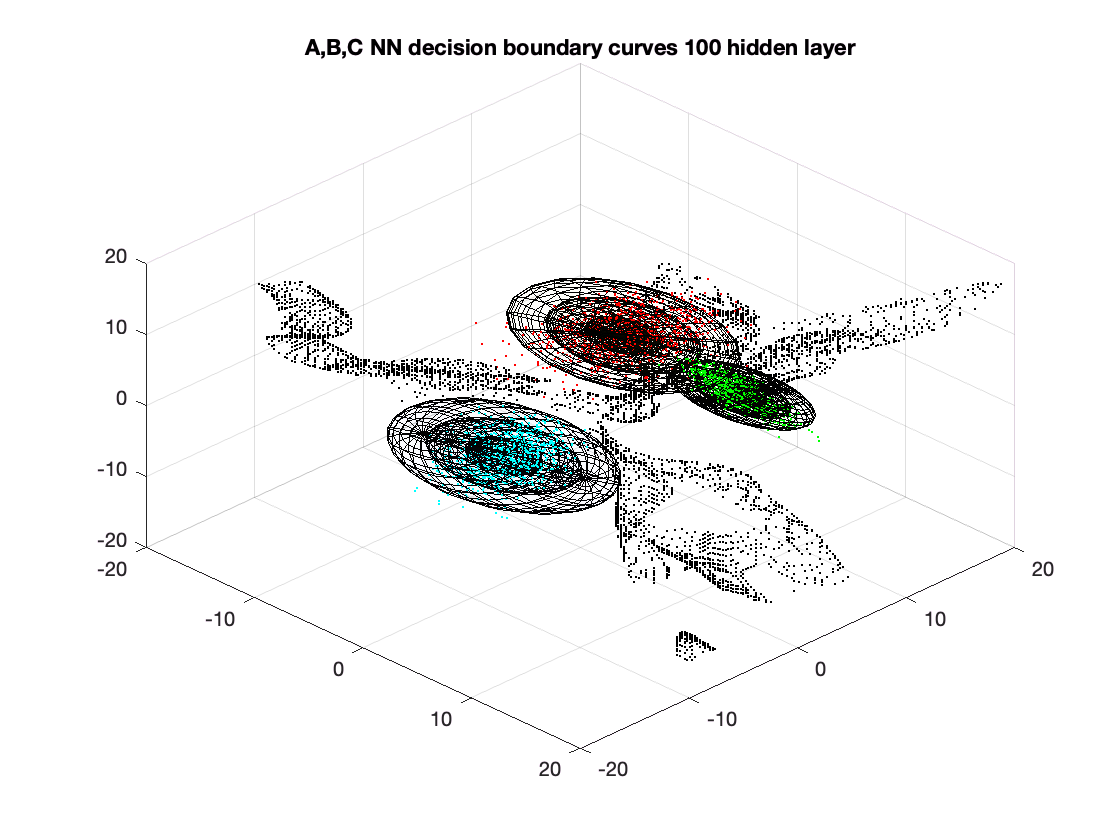


plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_4,boundary_BC_4,boundary_AC_4,box)
title('A,B,C NN decision boundary curves 100 hidden layer')
hold off;

### **4c) Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s).**

The neural network to learn the decision boundaries are depend on the number of hidden layers. If there is no hidden layer, the network only can solve the linear problem. Therefore, more hidden layer, produce more higher order function.

## **Q5 Discuss in detail why or why not the neural network will ever be able to produce decision boundaries equivalent to the Bayes boundaries.**

**If Neural Network replicate Bayes boundary: **

- Neural Network can produce similiar decision boundaries as to the bayes boundaries. 

- Bayes boundary is the optimal if the data's statisticial properties (e.g. mean & covariance, and distribution)   

**If Neural Network does not replicate Bayes boundary: **

- In order to learn what Bayes classifier "knows", we need to know the distirbution of data, mean and covariance of data. 

- If we have infinite number of data, but the dataset is randomly generated points. Then Neural Network will not produce decison boundaries equivalent. 

- If we have finite number of data, with known distirbution of data, mean and covariance of data, as the dataset beome large, it will very likely to produce decison boundaries equivalent to the Bayes boundaries.  

## **Q6 Assess whether or not the neural network boundaries are more or less sensitive to outliers than the Bayesian boundaries.**

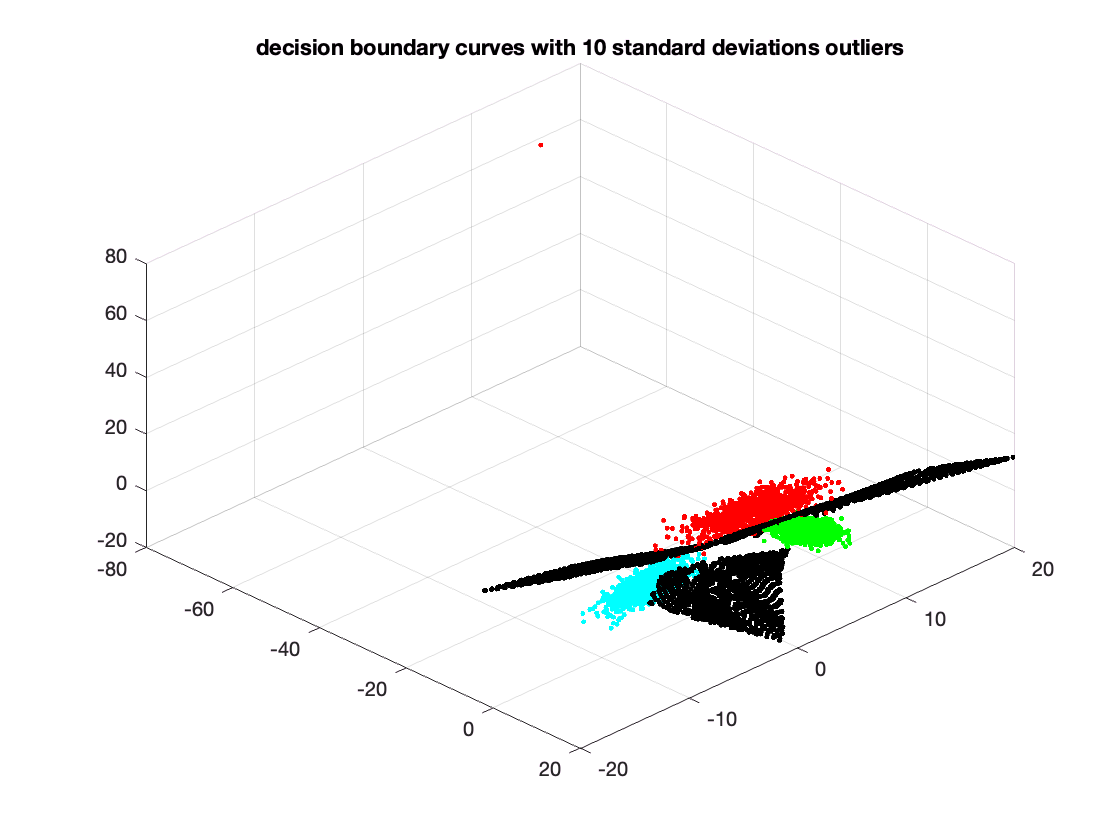

% For 10 standard deviations
std = 10;
outlier = outliers(std, A, muA, covA);
outlier_11 = outlier(1, :);
new_data = [A; outlier_11];

New_Data = [new_data;B;C];
New_Targets = [repmat(label_A, length(new_data), 1); repmat(label_B, 1000, 1); repmat(label_C, 1000, 1)];
net_6=create_nn(New_Data', New_Targets', 10);
data_nn_6 = net_6(box');
[boundary_AB_6, boundary_BC_6, boundary_AC_6] = nn_bound(data_nn_6', 0.01);


% plot_classes(new_data,B,C,mean_newA,muB,muC,cov_newA,covB,covC)
scatter3(new_data(:, 1), new_data(:, 2), new_data(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])

plot_boundary(boundary_AB_6,boundary_BC_6,boundary_AC_6,box)
title('decision boundary curves with 10 standard deviations outliers')

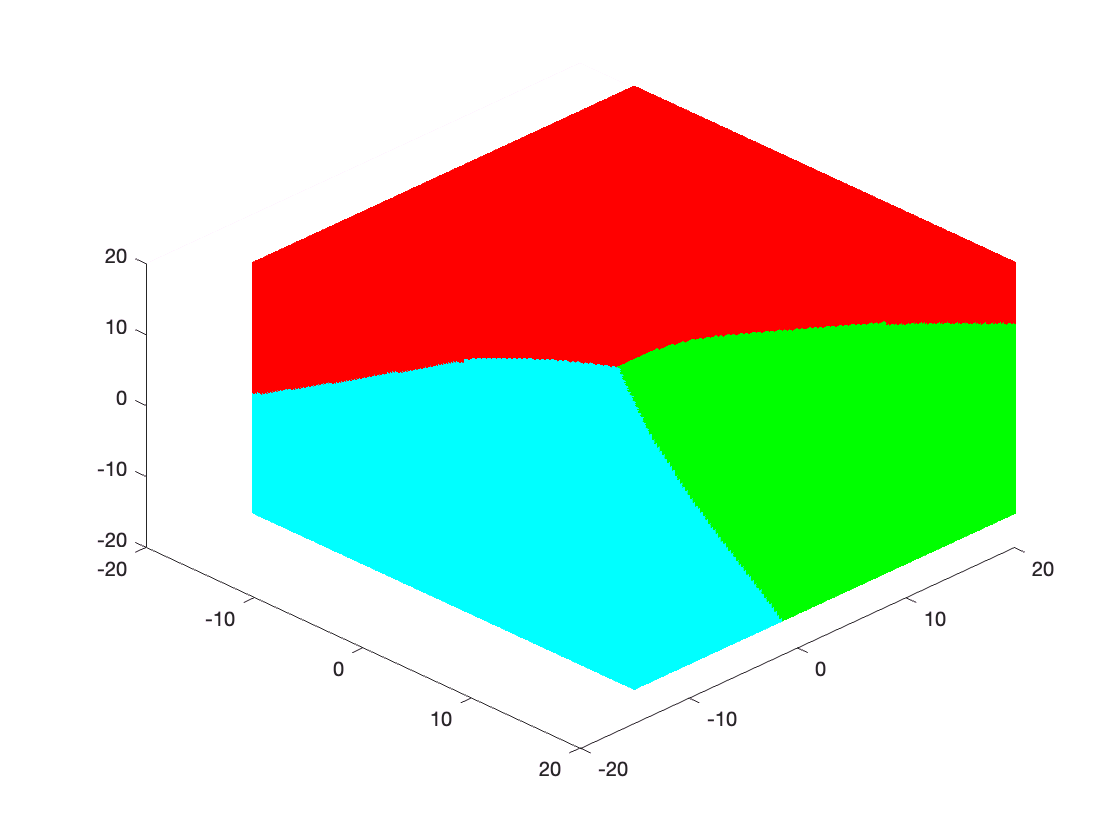


[class_a_6, class_b_6, class_c_6]=classifier_nn(data_nn_6');
plot_box(class_a_6,class_b_6,class_c_6,box)
hold off;

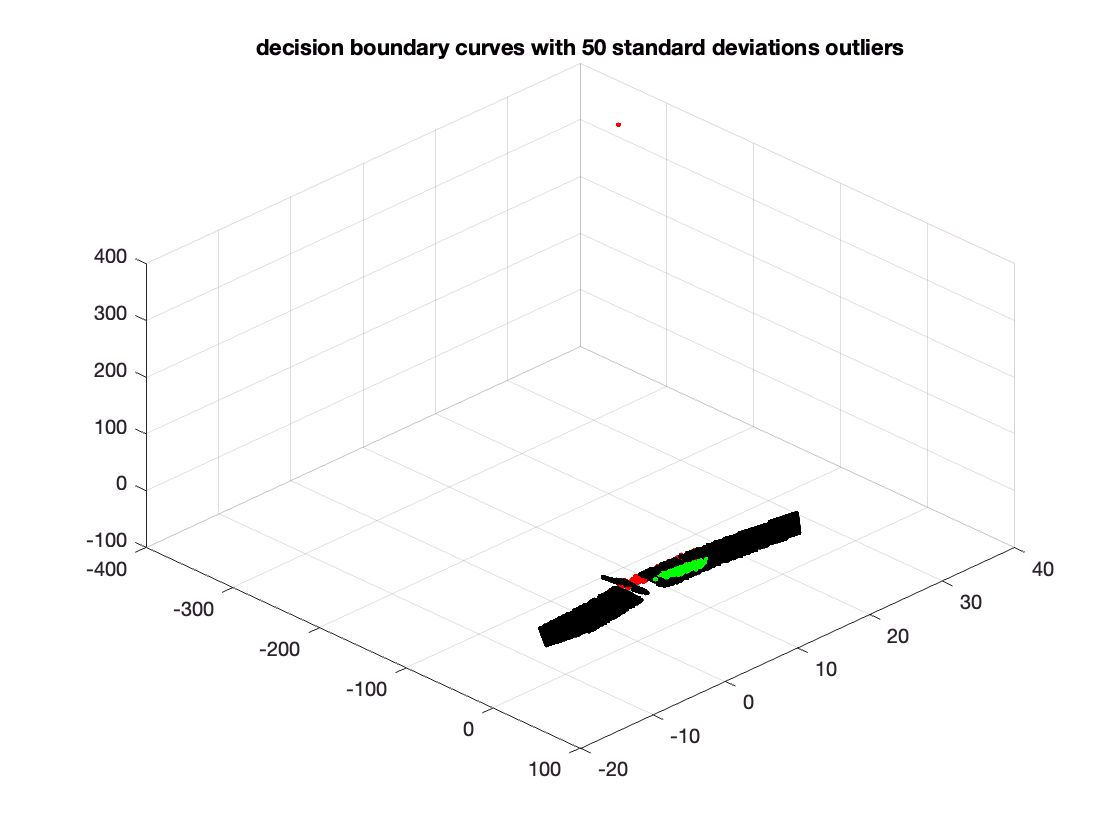



% For 50 standard deviations
std_1 = 50;
outlier_1 = outliers(std_1, A, muA, covA);
outlier_m = outlier_1(1, :);
new_data_1 = [A; outlier_m];

New_Data = [new_data_1;B;C];
New_Targets = [repmat(label_A, length(new_data_1), 1); repmat(label_B, 1000, 1); repmat(label_C, 1000, 1)];
net_6=create_nn(New_Data', New_Targets', 10);
data_nn_6 = net_6(box');
[boundary_AB_6, boundary_BC_6, boundary_AC_6] = nn_bound(data_nn_6', 0.01);
% plot_classes(new_data_1,B,C,mean_newA_1,muB,muC,cov_newA_1,covB,covC)

scatter3(new_data_1(:, 1), new_data_1(:, 2), new_data_1(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])


plot_boundary(boundary_AB_6,boundary_BC_6,boundary_AC_6,box)
title('decision boundary curves with 50 standard deviations outliers')

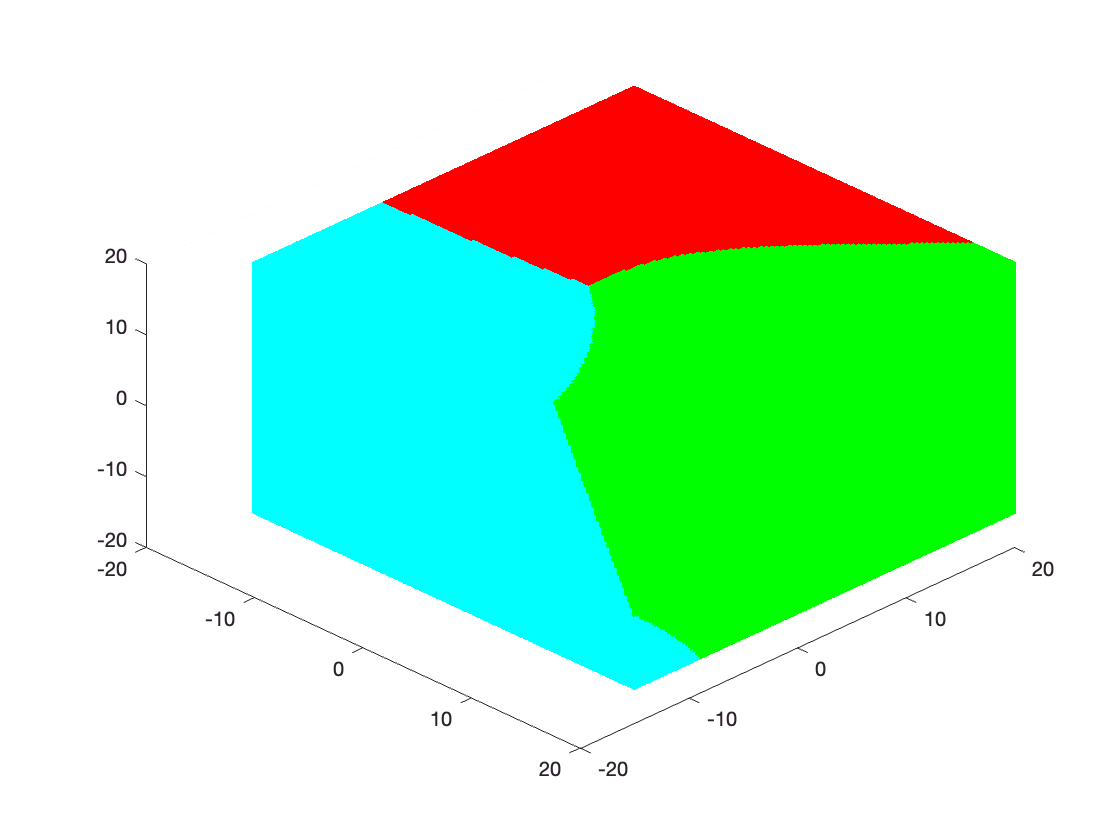



[class_a_6, class_b_6, class_c_6]=classifier_nn(data_nn_6');
plot_box(class_a_6,class_b_6,class_c_6,box)
hold off;

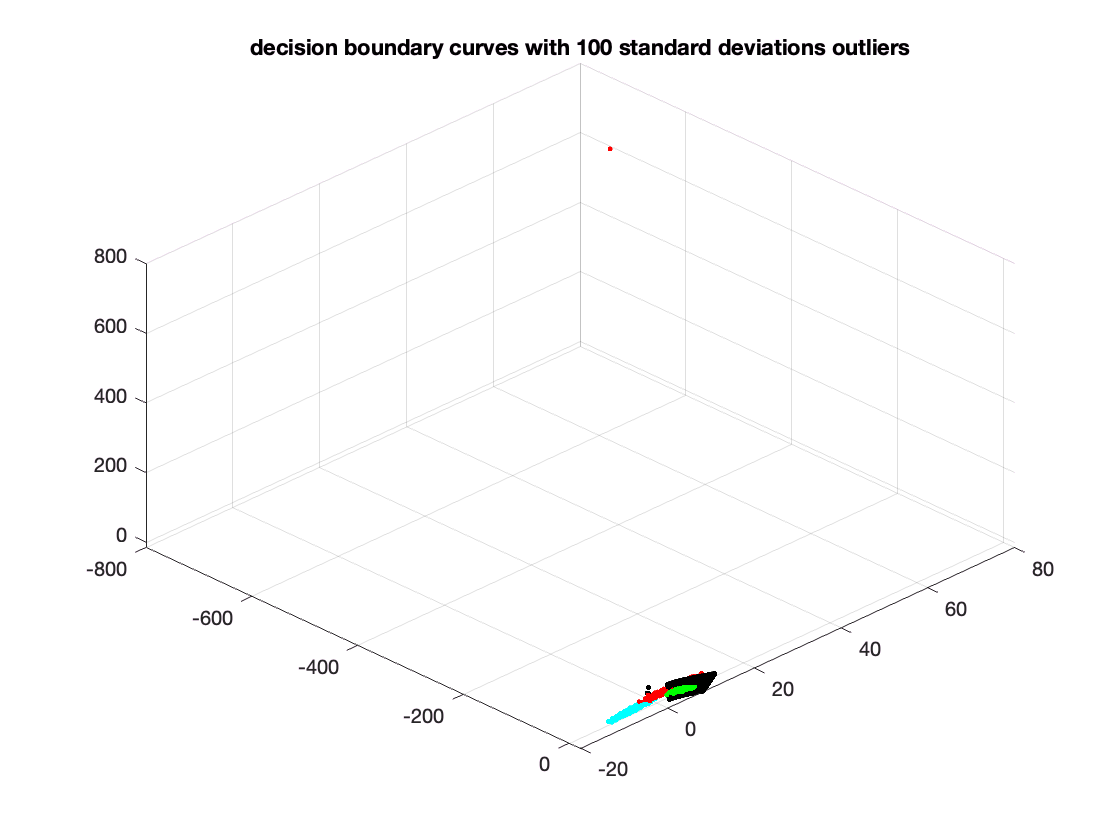



% For 100 standard deviations
std_2 = 100;
outlier_2 = outliers(std_2, A, muA, covA);
outlier_22 = outlier_2(1,:);
new_data_2 = [A; outlier_22];

New_Data = [new_data_2;B;C];
New_Targets = [repmat(label_A, length(new_data_2), 1); repmat(label_B, 1000, 1); repmat(label_C, 1000, 1)];
net_6=create_nn(New_Data', New_Targets', 10);
data_nn_6 = net_6(box');
[boundary_AB_6, boundary_BC_6, boundary_AC_6] = nn_bound(data_nn_6', 0.01);
% plot_classes(new_data_2,B,C,mean_newA_2,muB,muC,cov_newA_2,covB,covC)

scatter3(new_data_2(:, 1), new_data_2(:, 2), new_data_2(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])

plot_boundary(boundary_AB_6,boundary_BC_6,boundary_AC_6,box)
title('decision boundary curves with 100 standard deviations outliers')

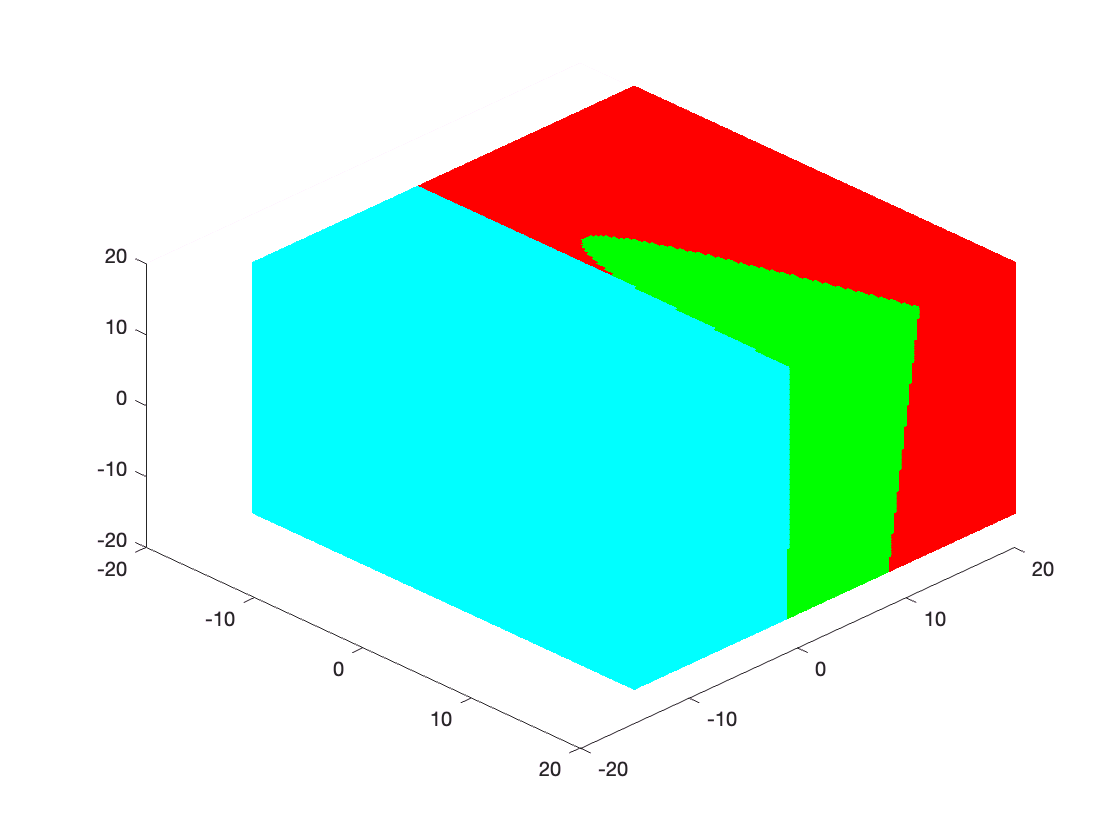


[class_a_6, class_b_6, class_c_6]=classifier_nn(data_nn_6');
plot_box(class_a_6,class_b_6,class_c_6,box)
hold off;


% For 10 standard deviations
std = 10;
outlier = outliers(std, A, muA, covA);
outlier_11 = outlier(1, :);
new_data = [A; outlier_11];

mean_newA = mean(new_data) % recalculate mean

mean_newA =    -0.0652    4.0065    7.0712


cov_newA = cov(new_data) % recalculate covariance

cov_newA =    10.7553    1.7386   -3.4013
    1.7386    5.1621    2.8422
   -3.4013    2.8422    7.4463


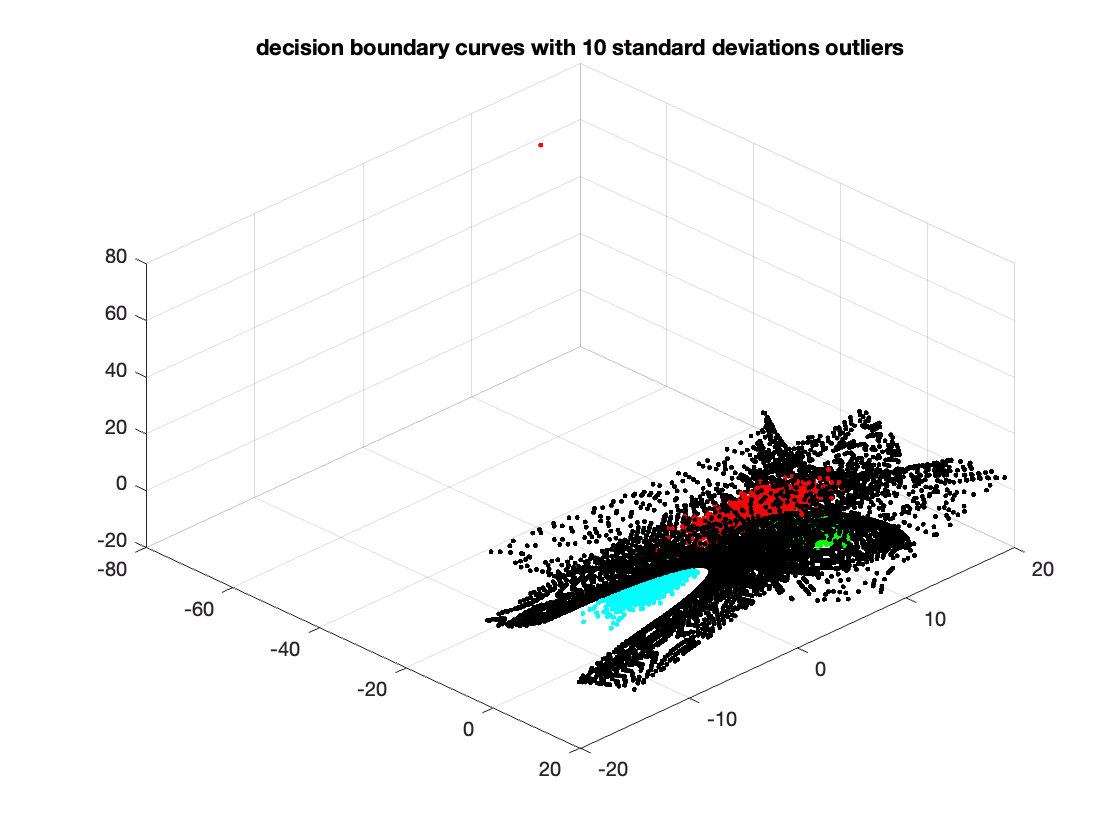



[boundary_AB_77, boundary_BC_77, boundary_AC_77] = bayes_bound(mean_newA,cov_newA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data,B,C,mean_newA,muB,muC,cov_newA,covB,covC)
scatter3(new_data(:, 1), new_data(:, 2), new_data(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])

plot_boundary(boundary_AB_77,boundary_BC_77,boundary_AC_77,box)
title('decision boundary curves with 10 standard deviations outliers')

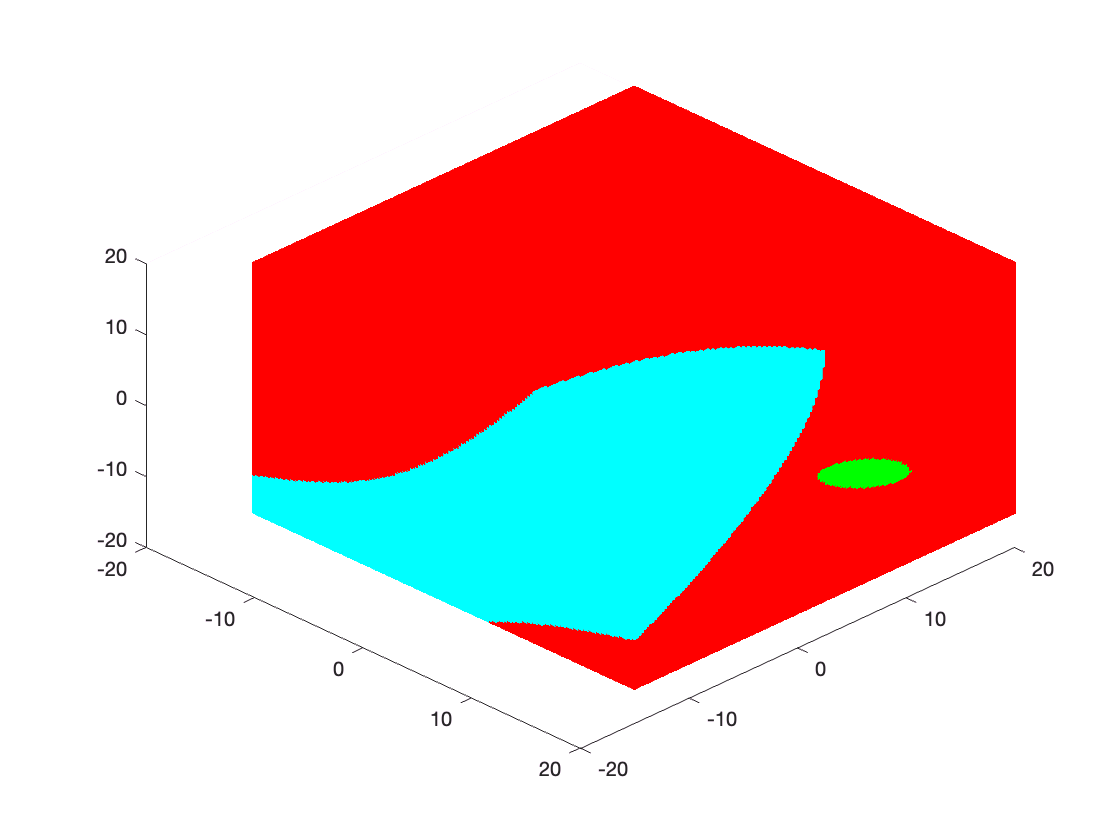


[class_a_4, class_b_4, class_c_4]=classifier(mean_newA,cov_newA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_4,class_b_4,class_c_4,box)
hold off;



% For 50 standard deviations
std_1 = 50;
outlier_1 = outliers(std_1, A, muA, covA);
outlier_m = outlier_1(1, :);
new_data_1 = [A; outlier_m];

mean_newA_1 = mean(new_data_1) % recalculate mean

mean_newA_1 =    -0.3262    4.0325    7.3560


cov_newA_1 = cov(new_data_1) % recalculate covariance

cov_newA_1 =   113.0378   -8.4454 -115.0027
   -8.4454    6.1761   13.9541
 -115.0027   13.9541  129.2157


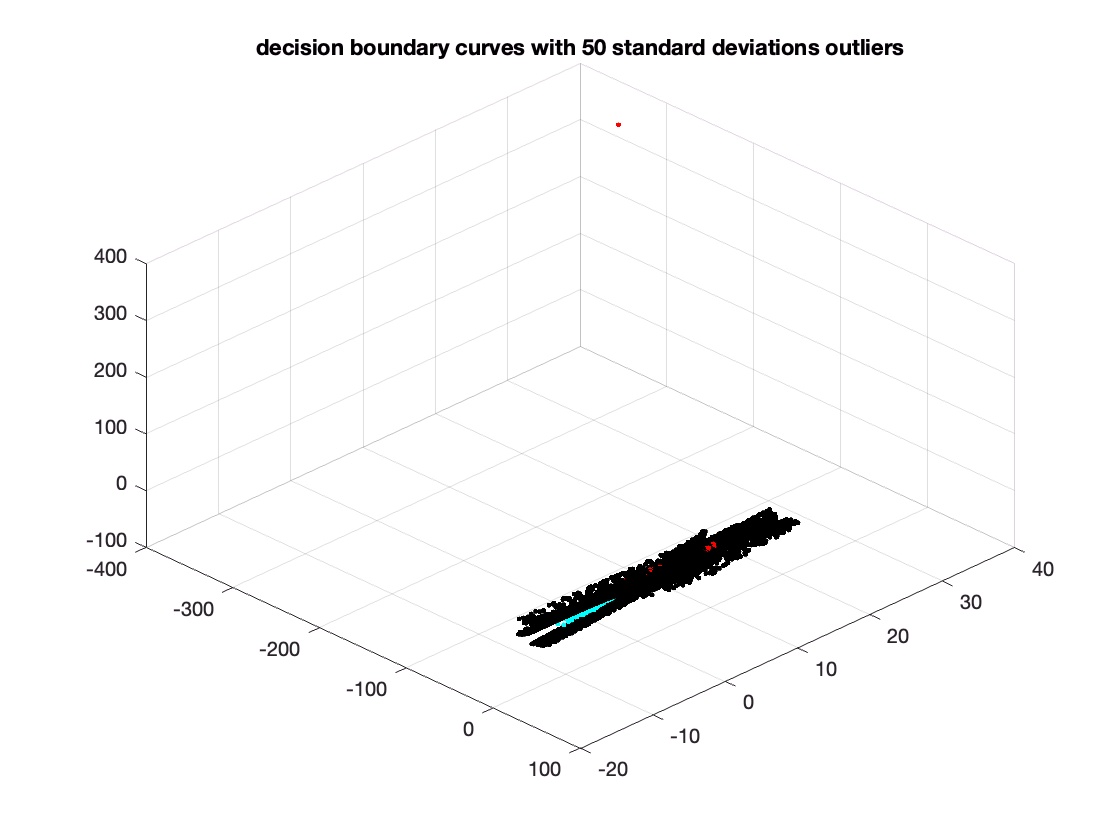


[boundary_AB_8, boundary_BC_8, boundary_AC_8] = bayes_bound(mean_newA_1,cov_newA_1,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data_1,B,C,mean_newA_1,muB,muC,cov_newA_1,covB,covC)

scatter3(new_data_1(:, 1), new_data_1(:, 2), new_data_1(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])


plot_boundary(boundary_AB_8,boundary_BC_8,boundary_AC_8,box)
title('decision boundary curves with 50 standard deviations outliers')

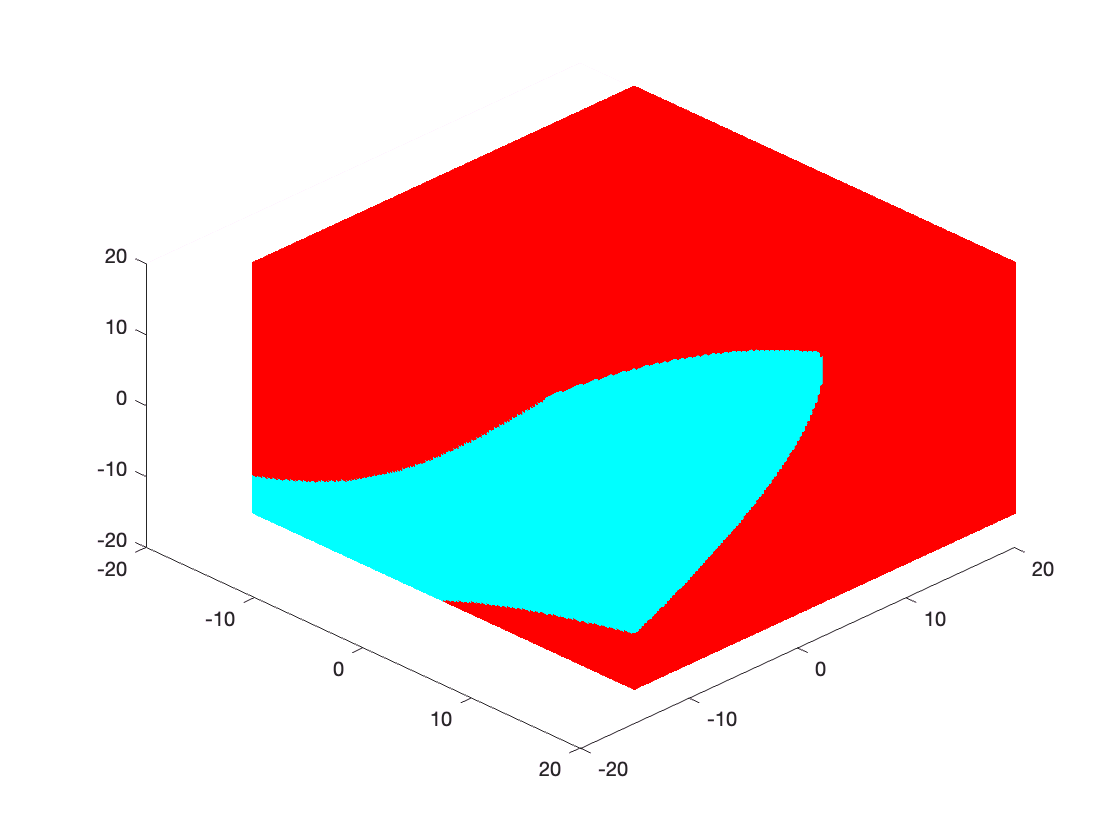


[class_a_5, class_b_5, class_c_5]=classifier(mean_newA_1,cov_newA_1,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_5,class_b_5,class_c_5,box)
hold off;



% For 100 standard deviations
std_2 = 100;
outlier_2 = outliers(std_2, A, muA, covA);
outlier_22 = outlier_2(1,:);
new_data_2 = [A; outlier_22];

mean_newA_2 = mean(new_data_2) % recalculate mean

mean_newA_2 =    -0.6525    4.0650    7.7119


cov_newA_2 = cov(new_data_2) % recalculate covariance

cov_newA_2 =   432.6706  -40.2704 -463.7570
  -40.2704    9.3448   48.6786
 -463.7570   48.6786  509.7447


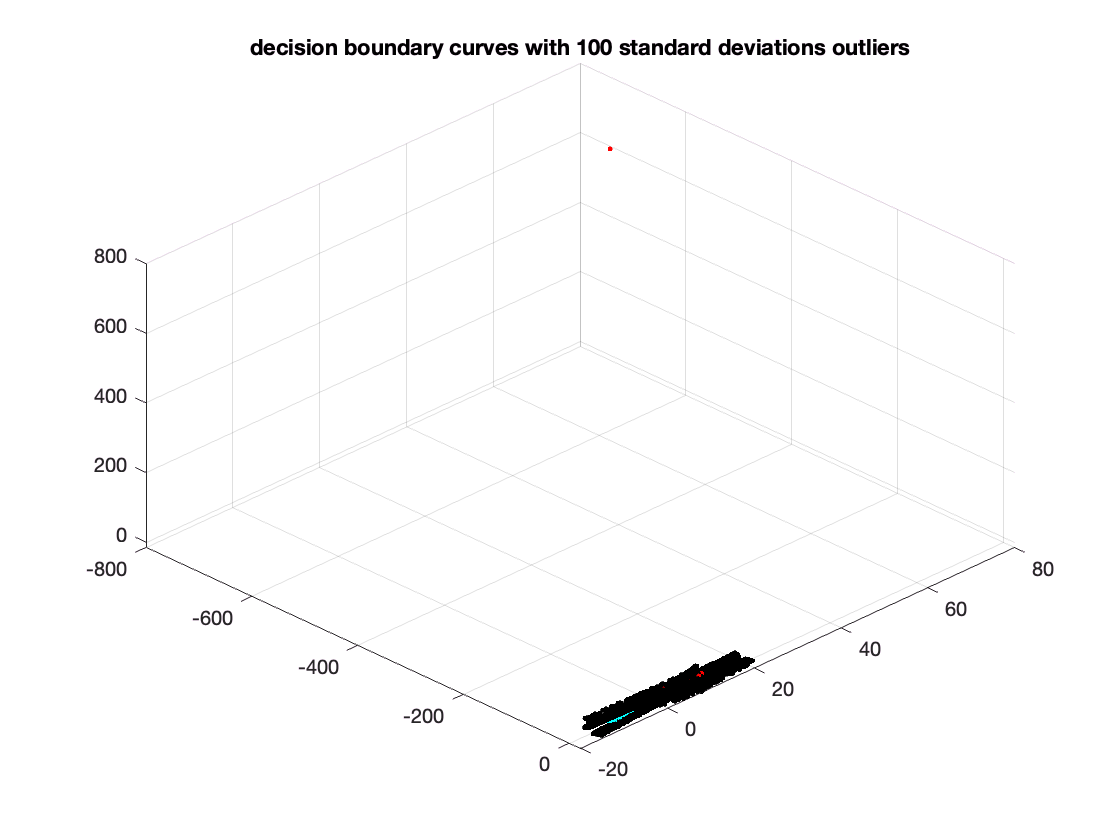



[boundary_AB_9, boundary_BC_9, boundary_AC_9] = bayes_bound(mean_newA_2,cov_newA_2,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data_2,B,C,mean_newA_2,muB,muC,cov_newA_2,covB,covC)

scatter3(new_data_2(:, 1), new_data_2(:, 2), new_data_2(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])


plot_boundary(boundary_AB_9,boundary_BC_9,boundary_AC_9,box)
title('decision boundary curves with 100 standard deviations outliers')

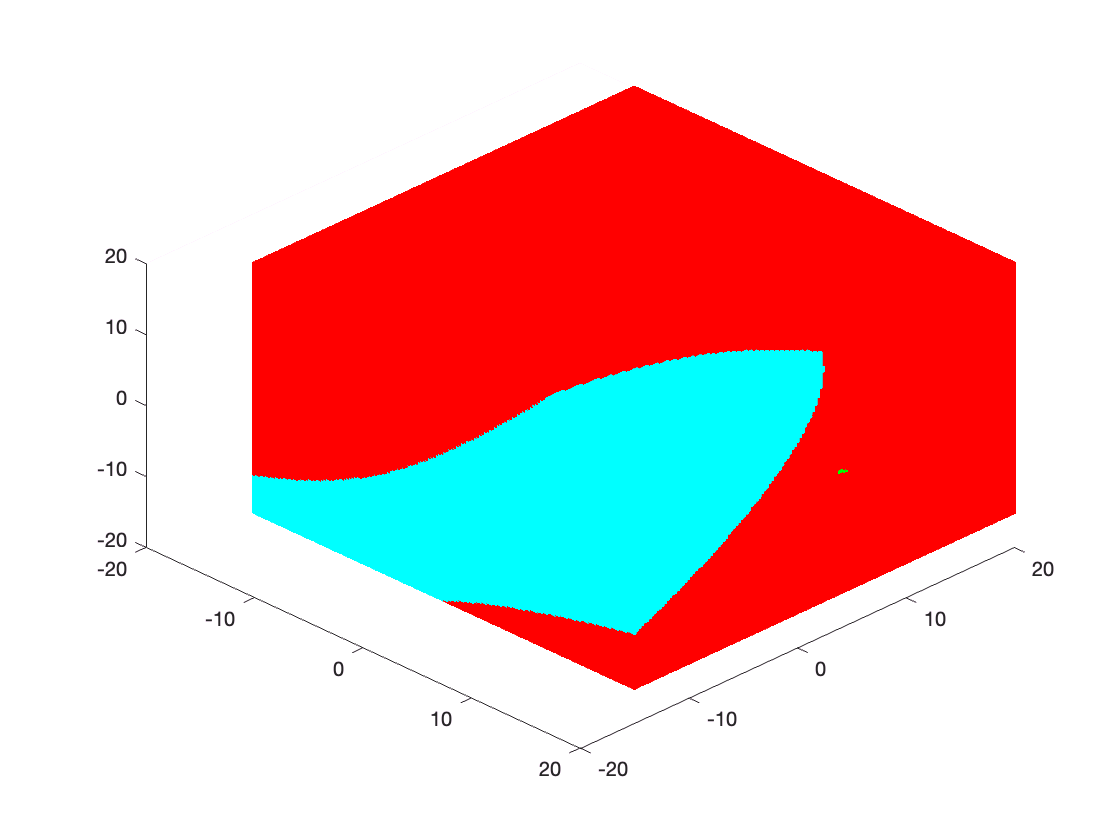




[class_a_6, class_b_6, class_c_6]=classifier(mean_newA_2,cov_newA_2,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_6,class_b_6,class_c_6,box)
hold off;

### Q6 Discussion

From the plot we got above, we can see that more far away outliner, more seriously impacted on nerual netwirk. The bayes boundaries is more sensitive for the outliner, since the decision boundaries has huge change at the first plot. But as the outliers change, e.g. outliers much far away from the most data, many outliers, Neural Network will have different performance. When Neural Network has much hidden layers, it can enhance the capability of NN to deal with outlieres.

And as the Bayes decision boundary are influenced by mean and covariance of data, and the outliers will change mean and covariance a lot, then it's very sensitive to outliers.

## **Q7 Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.**

### **May be remove the code, just discuss.**

x = Data';
t = Targets';

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 90/100;
net.divideParam.valRatio = 5/100;
net.divideParam.testRatio = 5/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x)

y =     1.0000    0.9997    1.0000    1.0000    1.0000    1.0000    1.0000    0.9976    0.9999    0.9997    1.0000    0.9915    0.9996    1.0000    0.9991    0.9999    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    0.9999    1.0000    0.9995    1.0000    0.9843    1.0000    1.0000    1.0000    0.9998    1.0000    1.0000    0.9803    0.9983    0.9992    1.0000    0.9995    0.9980    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    0.9993    1.0000    0.9999    0.9998
    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0000    0.0084    0.0000    0.0000    0.0009    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000    0.0155    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0196    0.0004    0.0001    0.0000    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0

e = gsubtract(t,y)

e =     0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0024    0.0001    0.0003    0.0000    0.0085    0.0004    0.0000    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0005    0.0000    0.0157    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0197    0.0017    0.0008    0.0000    0.0005    0.0020    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0007    0.0000    0.0001    0.0002
   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0000   -0.0084   -0.0000   -0.0000   -0.0009   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0002   -0.0000   -0.0155   -0.0000   -0.0000   -0.0000   -0.0002   -0.0000   -0.0000   -0.0196   -0.0004   -0.0001   -0.0000   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0

performance = perform(net,t,y)

performance = 0.0049

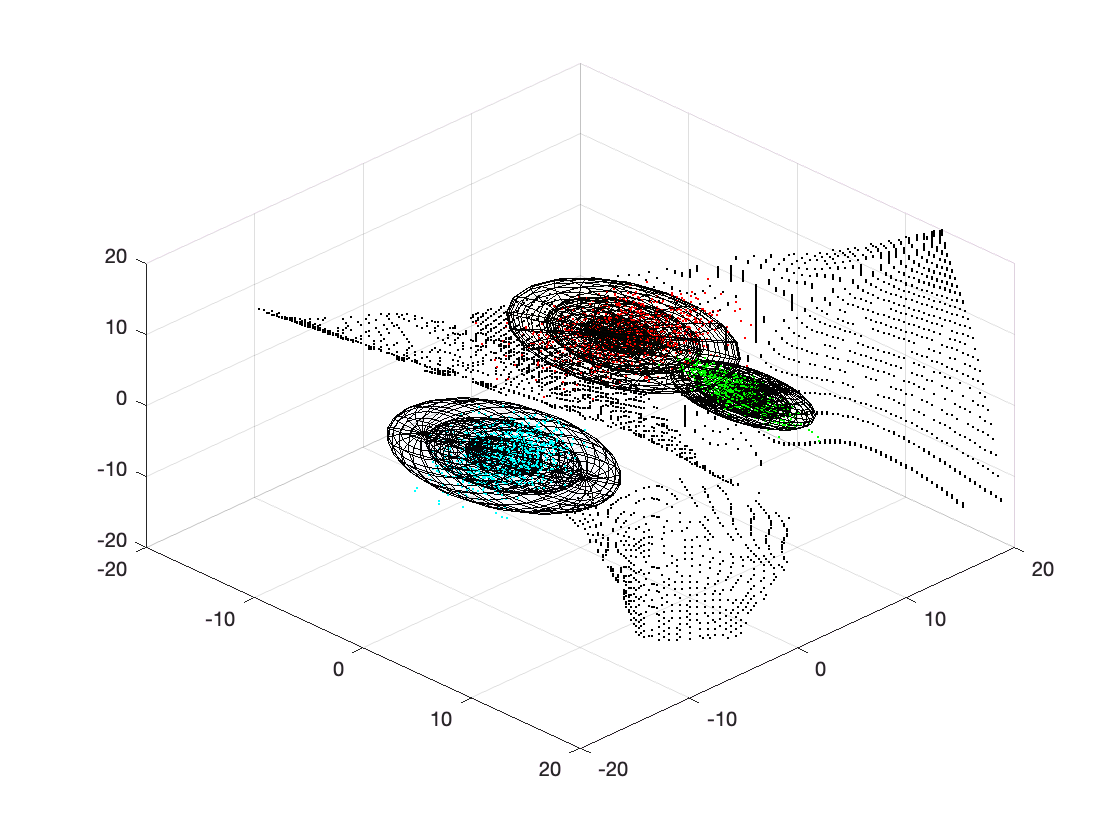

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

data_nn_7 = net(box');
[boundary_AB_7, boundary_BC_7, boundary_AC_7] = nn_bound(data_nn_7', 0.01);

plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_7,boundary_BC_7,boundary_AC_7,box)

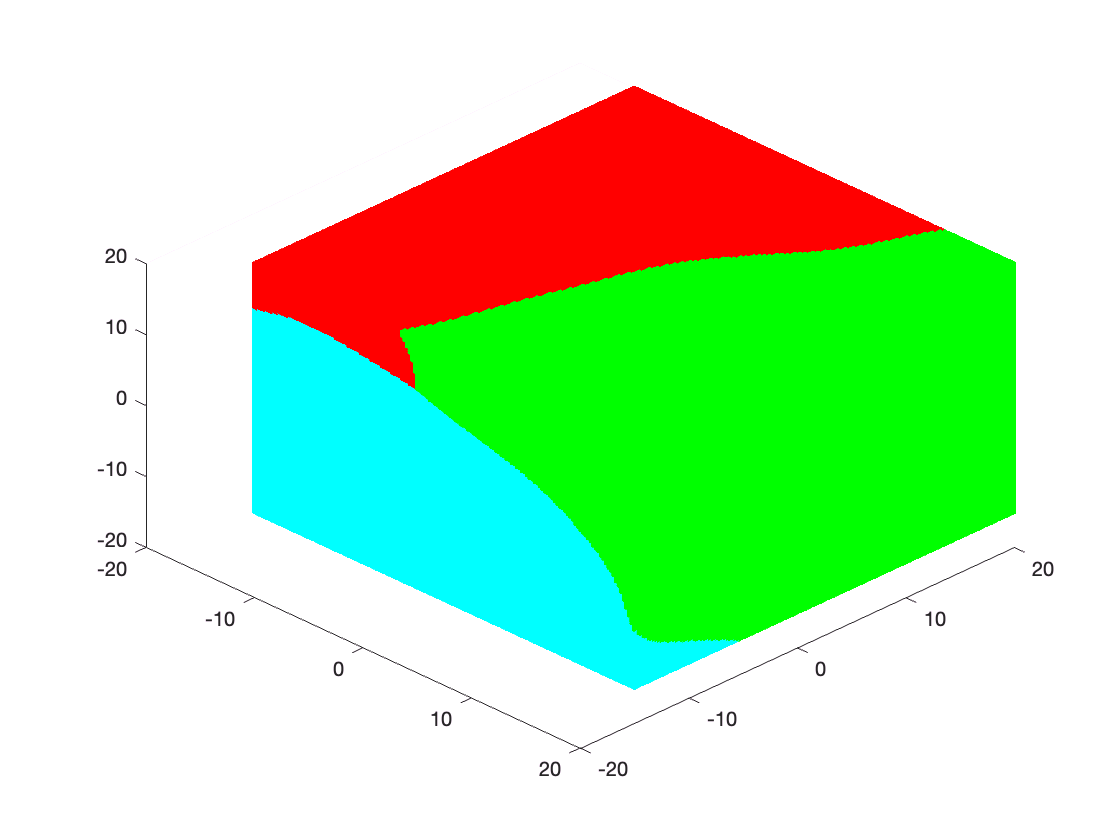


[class_a, class_b, class_c]=classifier_nn(data_nn_7');
plot_box(class_a,class_b,class_c,box)


x = Data';
t = Targets';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 5/100;
net.divideParam.valRatio = 5/100;
net.divideParam.testRatio = 90/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x)

y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9997    1.0000    1.0000    1.0000    0.9997    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

e = gsubtract(t,y)

e =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

performance = perform(net,t,y)

performance = 0.0128

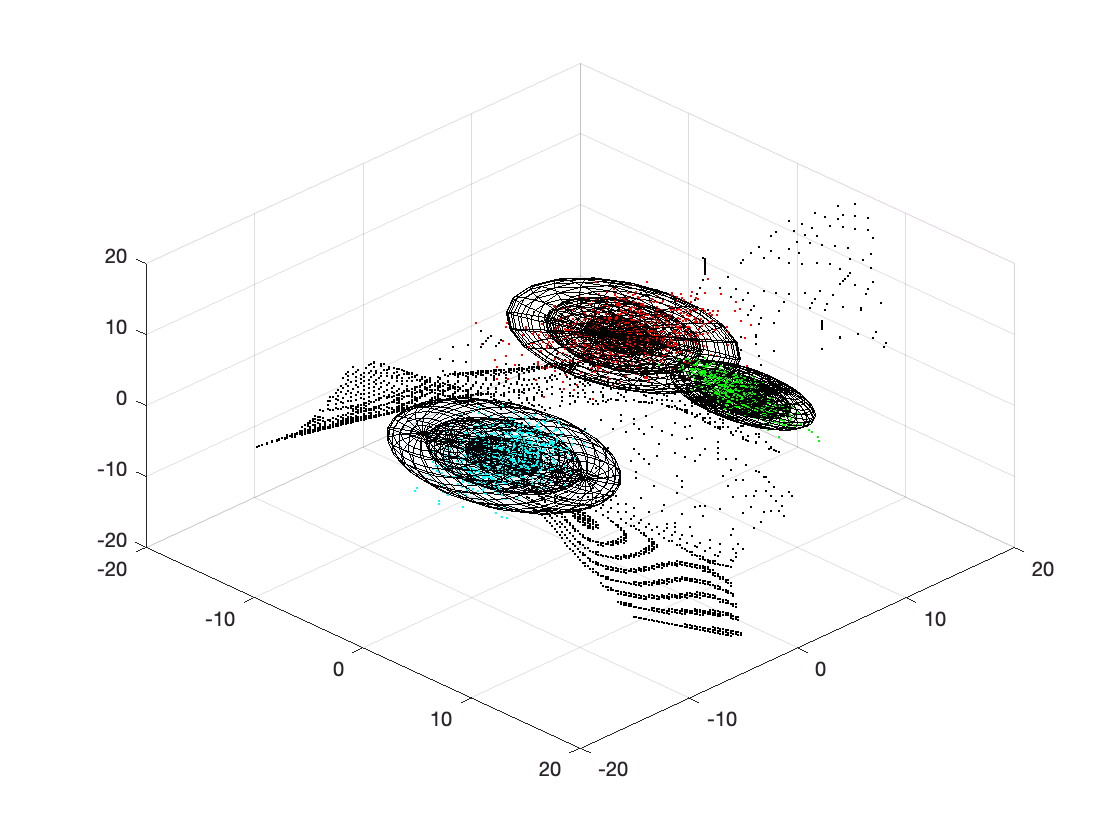

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

data_nn_71 = net(box');
[boundary_AB_71, boundary_BC_71, boundary_AC_71] = nn_bound(data_nn_71', 0.01);

plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_71,boundary_BC_71,boundary_AC_71,box)

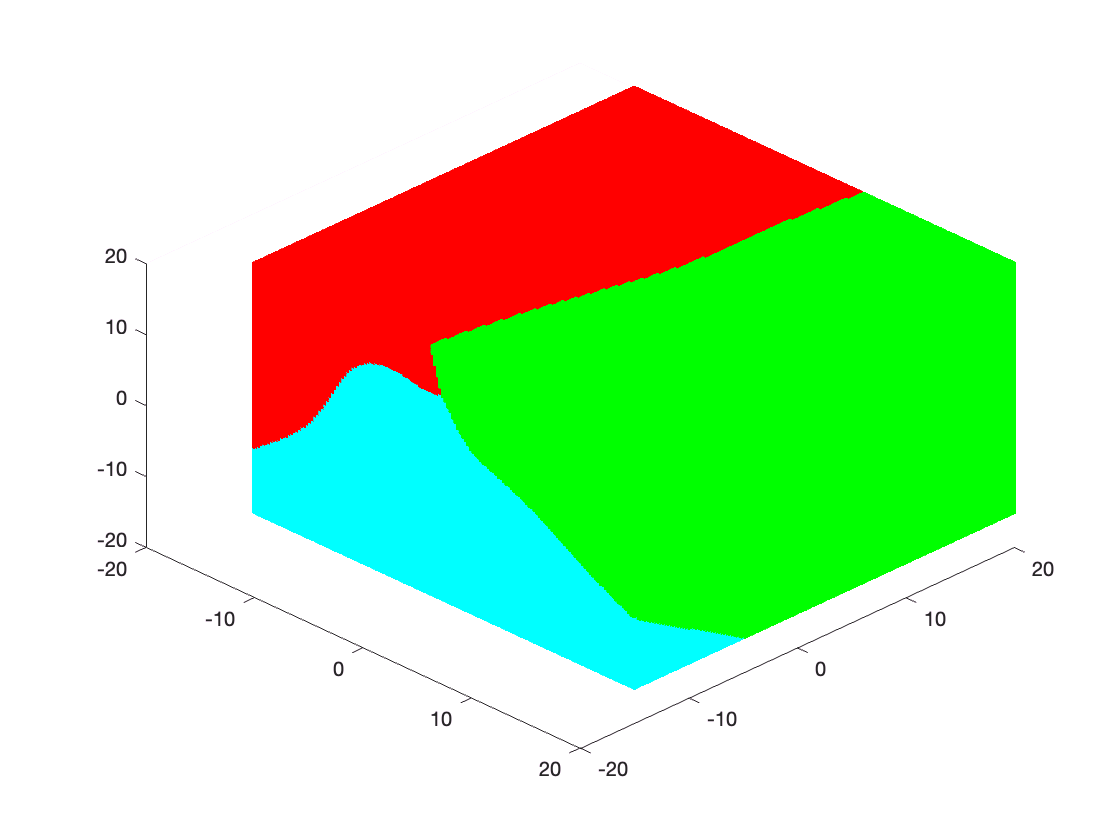


[class_a, class_b, class_c]=classifier_nn(data_nn_71');
plot_box(class_a,class_b,class_c,box)

### Q7 Discussion

If we have training set 90% and test set 10%,  we could get high accuracy as result. However, the test set is too small, it may not be possible to show the accuracy of the predictions for all the different scenarios. We cannot generalize the model except the dataset we have right now is bigger enough to carry almost all case the we need. And usually it may face overfitting issues, Neural Network learns well from training dataset, but when given new dataset to test, it performs not as good as training dataset. 

If we have training set 10% and test set 90%, which means test set cannot learn enough case/situation from the training. It will consequence end with potential bad model. 

Overall, the suitable amount of split trainning set and test set is important, we need to make sure Neural Network has enough data to learn but also avoid overfitting.

**New Function for ex3 here.**

function [boundary_ab, boundary_bc, boundary_ac] = nn_bound(data, epsilon)
boundary_ab = find(data(:, 1)<=epsilon & abs(data(:, 2) - data(:, 3)) <= epsilon);
boundary_bc = find(data(:, 2)<=epsilon & abs(data(:, 1) - data(:, 3)) <= epsilon);
boundary_ac = find(data(:, 3)<=epsilon & abs(data(:, 1) - data(:, 2)) <= epsilon);
end


function [class_a, class_b, class_c]=classifier_nn(data)
%base on the ex2 classifier function.
class_a = find(data(:, 1)> max(data(:, 2), data(:, 3)));
class_b = find(data(:, 2)> max(data(:, 1), data(:, 3)));
class_c = find(data(:, 3)> max(data(:, 1), data(:, 2)));
end

function net2 = create_nn(x,t,size)
trainFcn = 'trainscg';
hiddenLayerSize = size;
net2 = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net2.divideParam.trainRatio = 70/100;
net2.divideParam.valRatio = 15/100;
net2.divideParam.testRatio = 15/100;

% Train the Network
[net2,tr] = train(net2,x,t);
end


**Function from ex1, ex2 and provide by prof are here.**

function [class_a, class_b, class_c]=classifier(mua,cova,priora,mub,covb,priorb,muc,covc,priorc,box)
gk_a = discriment_f(box,priora, mua, cova);
gk_b = discriment_f(box,priorb, mub, covb);
gk_c = discriment_f(box,priorc, muc, covc);

class_a = find(gk_a> max(gk_b, gk_c));
class_b = find(gk_b> max(gk_a, gk_c));
class_c = find(gk_c> max(gk_a, gk_b));
end

function [boundary_ab, boundary_bc, boundary_ac] = bayes_bound(mua,cova,priora,mub,covb,priorb,muc,covc,priorc,box)
epsilon =  0.1; % if epsilon is small like 0.00001, abs(gk_a-gk_b) will be 0 show in Matlab.
gk_a = discriment_f(box,priora, mua, cova);
gk_b = discriment_f(box,priorb, mub, covb);
gk_c = discriment_f(box,priorc, muc, covc);

boundary_ab = find(abs(gk_a-gk_b)<=epsilon);
boundary_bc = find(abs(gk_b-gk_c)<=epsilon);
boundary_ac = find(abs(gk_a-gk_c)<=epsilon);
end

function g_x = discriment_f(x,prior_prob, mu, sigma)
% discriment function follows from equation 67 in Ch2.
W_i = (-1/2)*inv(sigma);
w_i = inv(sigma)*mu';
w_i_0 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma))+log(prior_prob);
g_x = sum((x*W_i.').*x,2).'+w_i'*x'+w_i_0;
g_x = g_x.';


end

function m = outliers(std, data, mu, cov)

    [e, v] = eigs(cov);
    data = std' * sqrt(v) * e * data.'; 
    m = data.' + mu;
    
end

function plot_class_A(a,b,c,box)

classify_a = box(a,:);
classify_b = box(b,:);
classify_c = box(c,:);


% only plot class A to see the boundary clear. 
plot3(classify_a(:,1),classify_a(:,2),classify_a(:,3),'Marker',".","LineStyle","none","Color",[1 0 0])
hold on
plot3(classify_b(:,1),classify_b(:,2),classify_b(:,3),'Marker',".","LineStyle","none","Color",[0 1 0])
plot3(classify_c(:,1),classify_c(:,2),classify_c(:,3),'Marker',".","LineStyle","none","Color",[0 1 1])
hold off
view([45 45])

end


function plot_box(a,b,c,box)

classify_a = box(a,:);
classify_b = box(b,:);
classify_c = box(c,:);

plot3(classify_a(:,1),classify_a(:,2),classify_a(:,3),'Marker',".","LineStyle","none","Color",[1 0 0])
hold on
plot3(classify_b(:,1),classify_b(:,2),classify_b(:,3),'Marker',".","LineStyle","none","Color",[0 1 0])
plot3(classify_c(:,1),classify_c(:,2),classify_c(:,3),'Marker',".","LineStyle","none","Color",[0 1 1])
hold off
view([45 45])

end

function plot_classes(A,B,C,muA,muB,muC, covA,covB,covC)

scatter3(A(:, 1), A(:, 2), A(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])

plot_ellipsoids(muA,covA)
plot_ellipsoids(muB,covB)
plot_ellipsoids(muC,covC)
view([45,45])

end

function plot_boundary(boundary_1, boundary_2, boundary_3, box)
%hold on
% those plot follows the same logic. 
boundary_1 = box(boundary_1,:);
boundary_2 = box(boundary_2,:);
boundary_3 = box(boundary_3,:);

plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",[ 0, 0, 0])

hold off

end

function m = deTransfer(std, data, mu, cov)
    [E, v] = eigs(cov);
    data = reshape(data, [],3);
    data_1 = std' * sqrt(v) * E * data.';
    m = data_1.' + mu;
    m = [reshape(m(:, 1), 21, 21); reshape(m(:, 2), 21, 21); reshape(m(:, 3), 21, 21)];
    
       
end

function plot_ellipsoids(mu,cov_matrix)
[x,y,z] = ellipsoid(0,0,0,1,1,1);

Std_1_Data = deTransfer(1, [x,y,z], mu, cov_matrix);

n = size(Std_1_Data,2);

surf(Std_1_Data(1:n,:),Std_1_Data(n+1:2*n,:),Std_1_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');


Std_2_Data = deTransfer(2, [x,y,z], mu, cov_matrix);
surf(Std_2_Data(1:n,:),Std_2_Data(n+1:2*n,:),Std_2_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');


Std_3_Data = deTransfer(3, [x,y,z], mu, cov_matrix);

surf(Std_3_Data(1:n,:),Std_3_Data(n+1:2*n,:),Std_3_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');

end

function data = Gaussion_Data(k, d, mu, cov)
%     [e1, v1] = eigs(cov); % e is eigenvectors; v is eigenvalues
%     data = randn(k, d)* sqrt(v1) * e1' + transpose(mu);

data  = randn(k,d);
[E,v] = eigs(cov);
data = v^(1/2) * E * data.';
data = data.' + mu;
end


function transform = trans(data,m,sigma)
%     [e2, v2] = eig(cov(data));
%     A = e2 * 1/sqrt(v2);
%     transform = data * A;

%%whitening transformation to get covariance matrix to identity matrix. 
data = data-mean(data);
[E,v] = eigs(cov(data));
Y = E*v^(-1/2);
X = data * Y;

%%coloring transformation to get the exact mean and covariance matrix. 
[E1,v1] = eigs(sigma);
Y = v1^(1/2) * X';
transform = E1 * Y;
transform = transform'+m;
end



% professor gives this function. 
function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end